# Data Processing - Impedance

### 내부저항

impedance the fields are: 

Sense_current: Current in sense branch (Amps) 

Battery_current: Current in battery branch (Amps) 

Current_ratio: Ratio of the above currents 

Battery_impedance: Battery impedance (Ohms) computed from raw data 

Rectified_impedance: Calibrated and smoothed battery impedance(Ohms) 

**Re: Estimated electrolyte resistance(Ohms) <= ohm 저항 = 수명과 관련 **

Rct: Estimated charge transfer resistance(Ohms) <= 충전 상태와 관련 

비슷한 실험방법으로 측정해 보았다.

뒤쪽으로 선형성을 보이나 앞쪽에서 비선형성이 보여서 사용하기는 어려울 것 같다.

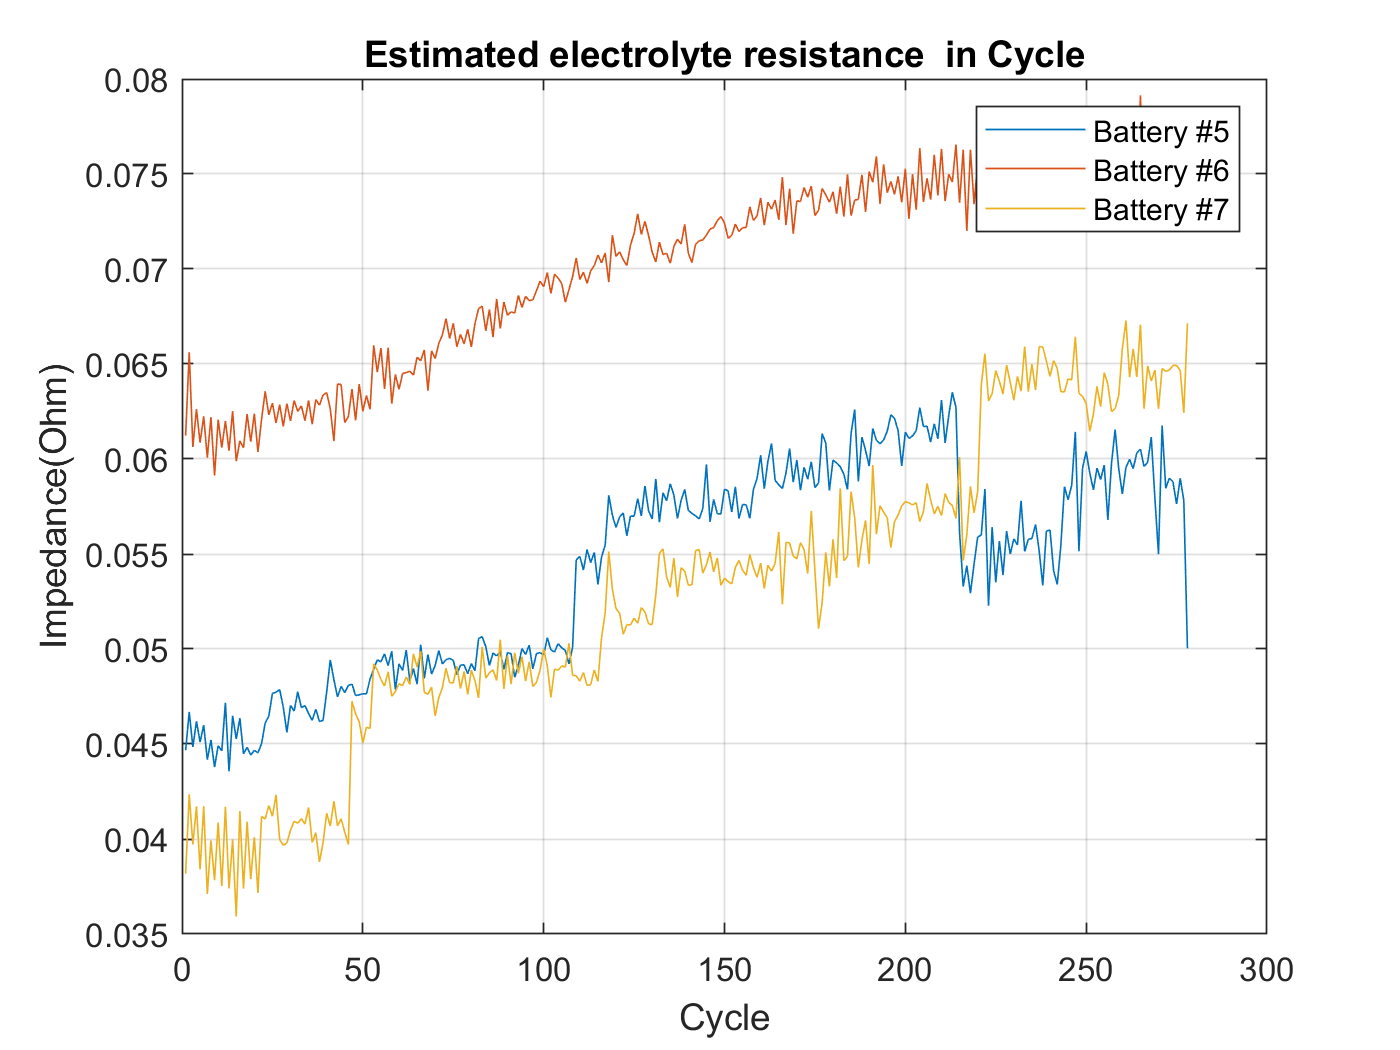

clear 
close all 

load ../B0005.mat
load ../B0006.mat
load ../B0007.mat
load ../B0018.mat

%%%%%%% Re 

re5 = extract_impedance_re(B0005);
re6 = extract_impedance_re(B0006);
re7 = extract_impedance_re(B0007);
figure
plot(re5), hold on, plot(re6), plot(re7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance  in Cycle')

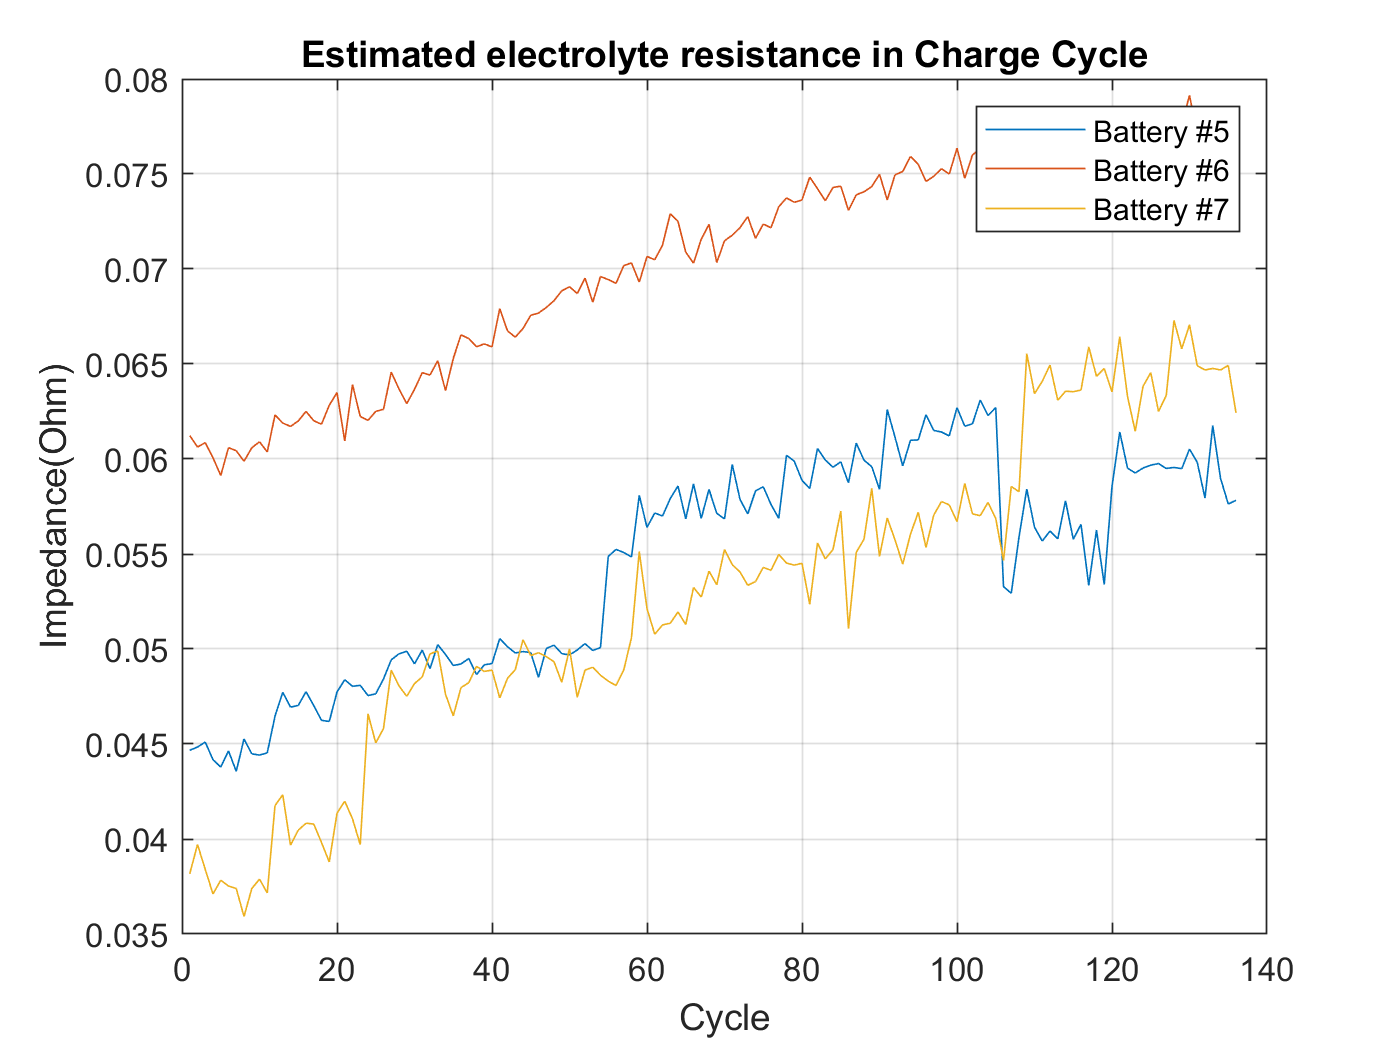



%%%%%%% Re - charge
re5c = extract_impedance_re_charge(B0005);
re6c = extract_impedance_re_charge(B0006);
re7c = extract_impedance_re_charge(B0007);
figure
plot(re5c), hold on, plot(re6c), plot(re7c)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Charge Cycle')

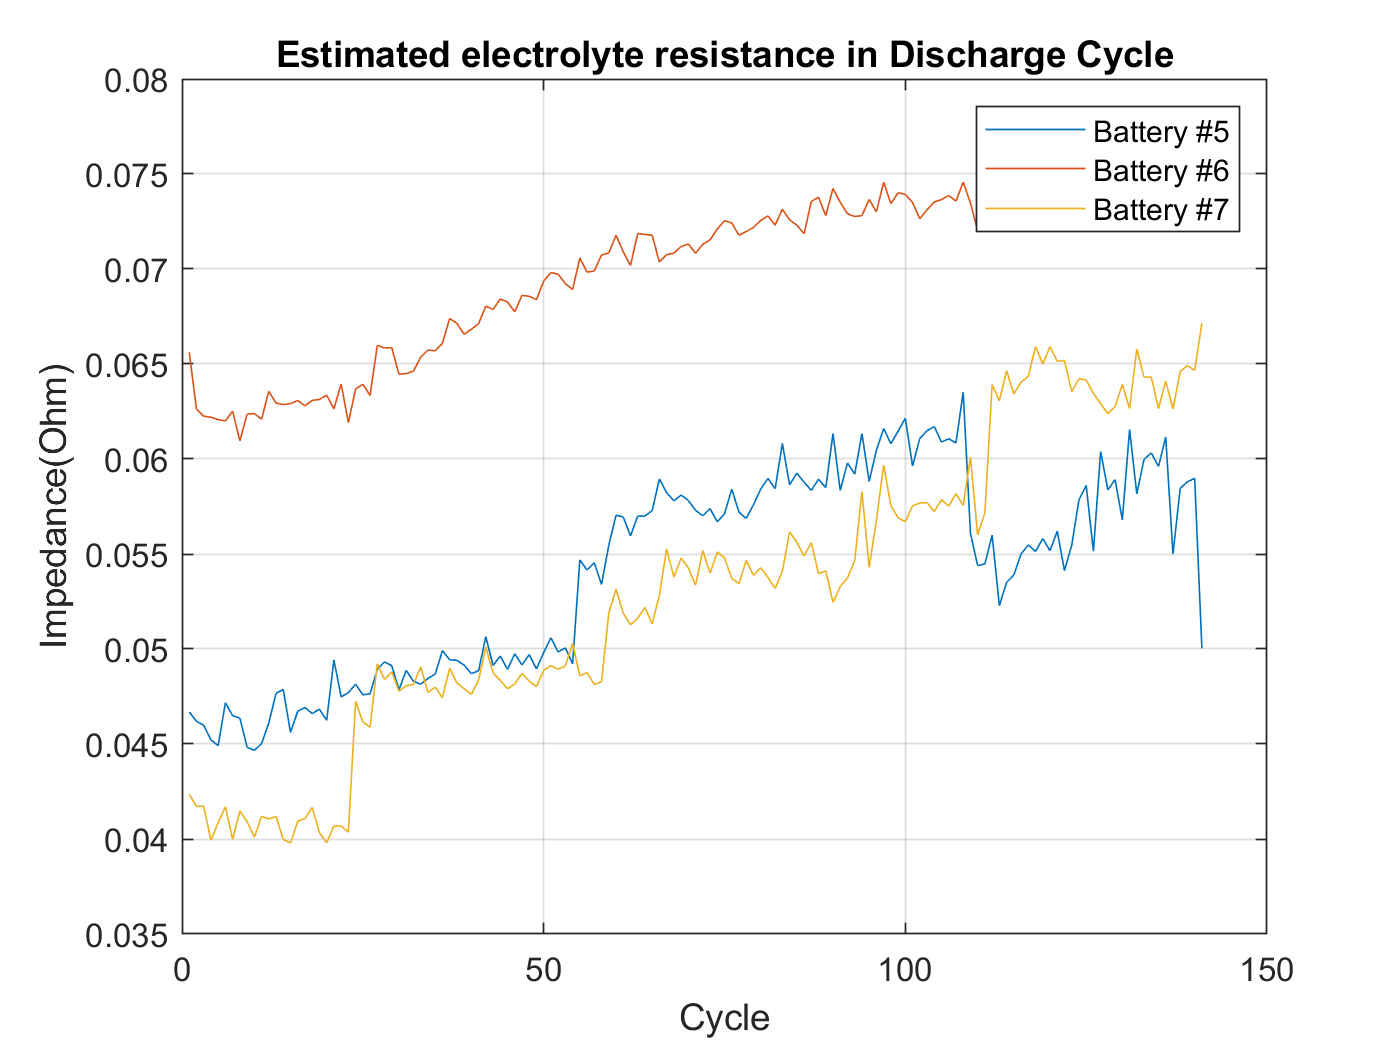



%%%%%%% Re - discharge

re5d = extract_impedance_re_discharge(B0005);
re6d = extract_impedance_re_discharge(B0006);
re7d = extract_impedance_re_discharge(B0007);
figure
plot(re5d), hold on, plot(re6d), plot(re7d)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Discharge Cycle')

측정된 Re Rct 로 그림을 그리는것이 잘 되지 않는다.


BAT1 =B0005;


%%%%%%%%%%%%%%% calculate ohm by Voltage and current 

items = size(BAT1.cycle,2)

items = 616

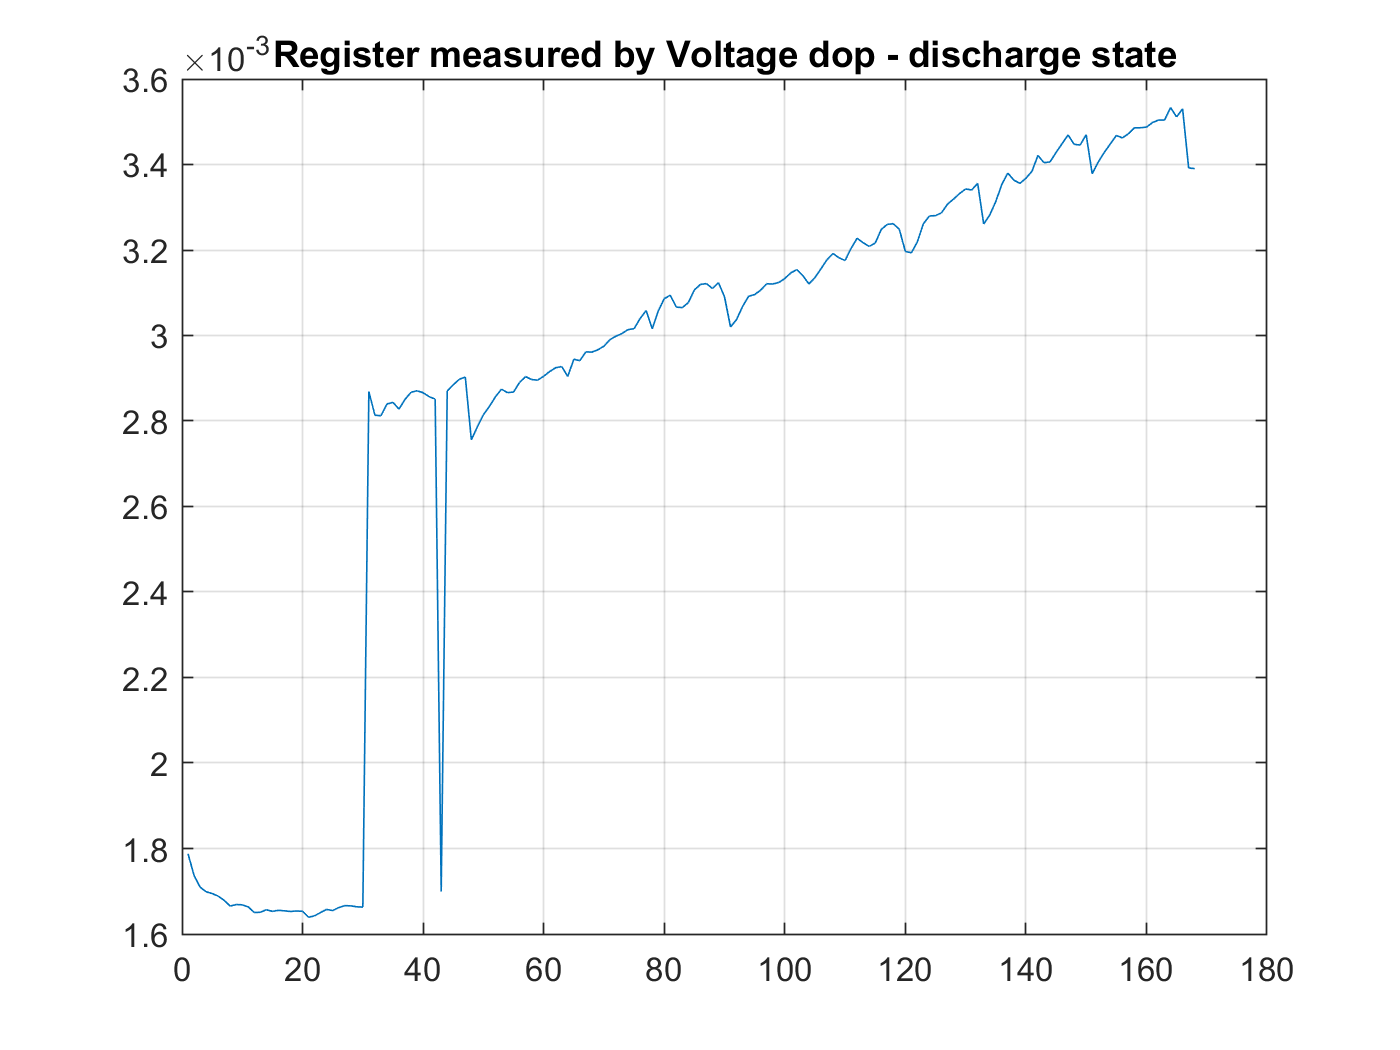

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(BAT1.cycle(i).type, 'discharge')
        deltaV = BAT1.cycle(i).data.Voltage_measured(start_index) -  BAT1.cycle(i).data.Voltage_measured(measure_index);
        deltaT = BAT1.cycle(i).data.Time(measure_index) - BAT1.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  BAT1.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = BAT1.cycle(i).data.Time(measure_index) ;
        
        %BAT1.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end

figure
plot(ohm)

title("Register measured by Voltage dop - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on

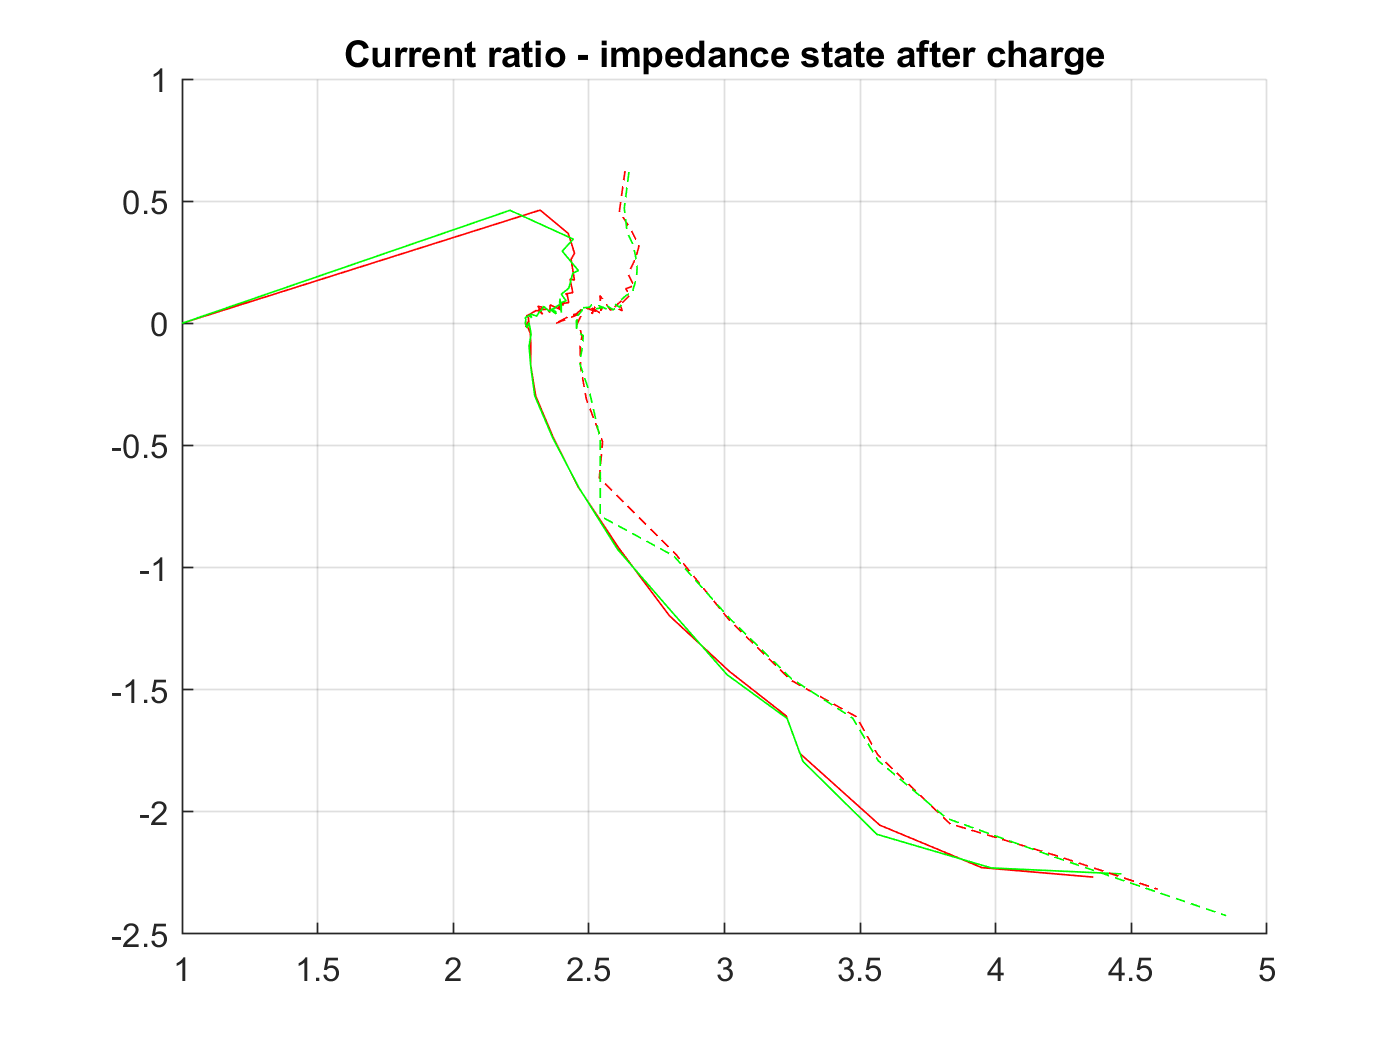

%%% Registor  Current_ratio

figure 
hold on
% after charge 
plot(B0005.cycle(41).data.Current_ratio,'r-')
plot(B0005.cycle(45).data.Current_ratio,'g-')
plot(B0005.cycle(607).data.Current_ratio,'r--')
plot(B0005.cycle(611).data.Current_ratio,'g--')
hold off
title("Current ratio - impedance state after charge")
grid on

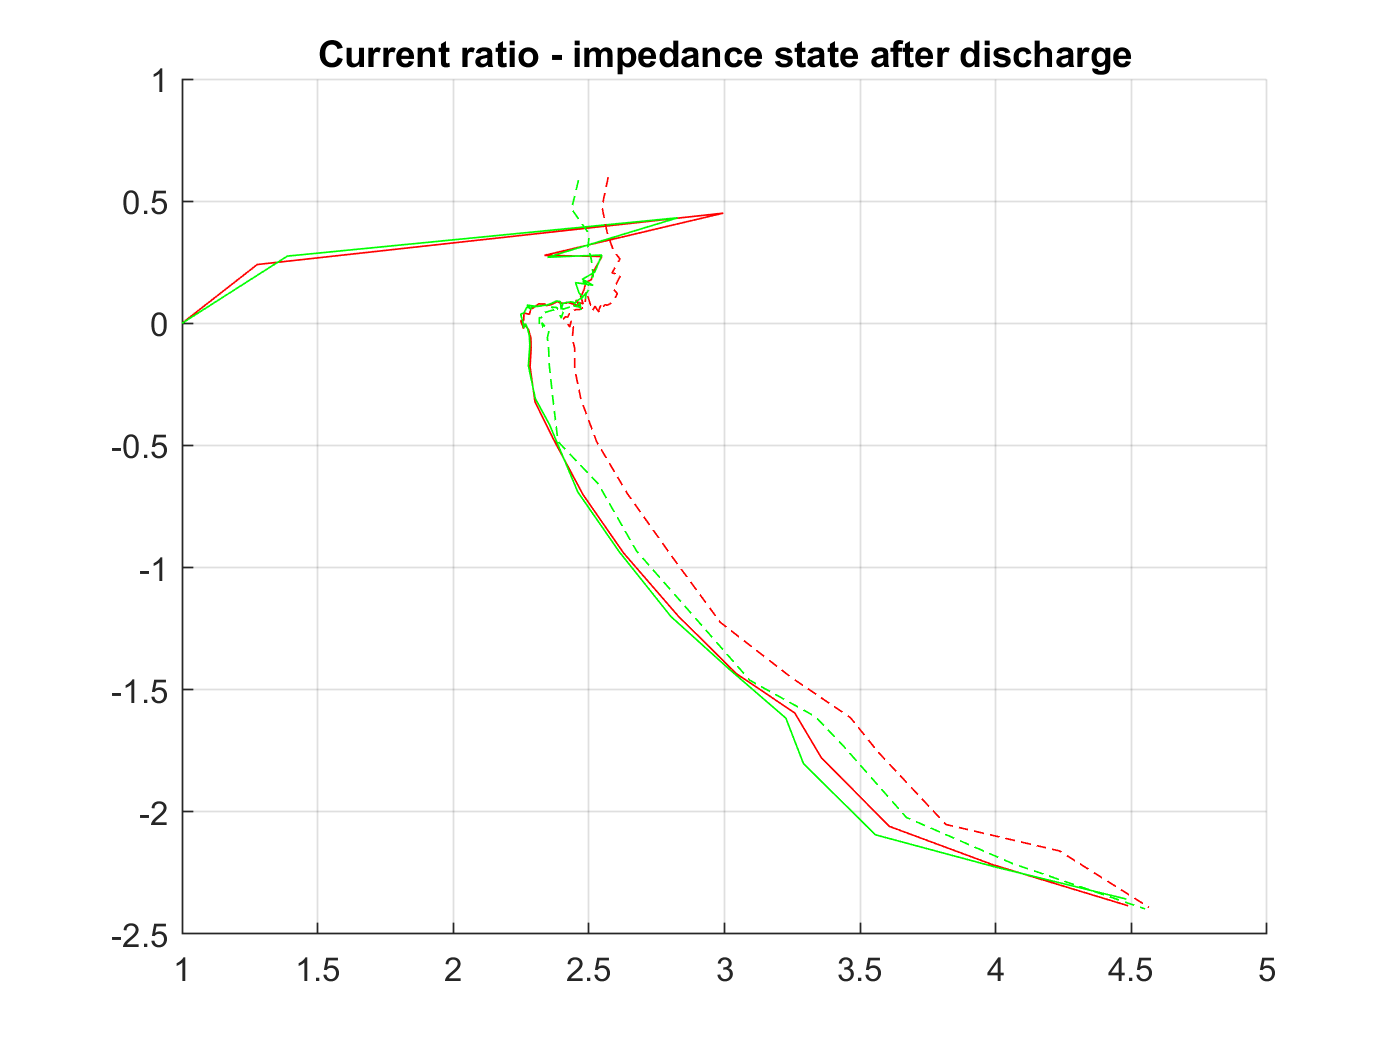


figure 
hold on
% after didscahage 43 47 
plot(B0005.cycle(43).data.Current_ratio,'r-')
plot(B0005.cycle(47).data.Current_ratio,'g-')
plot(B0005.cycle(609).data.Current_ratio,'r--')
plot(B0005.cycle(615).data.Current_ratio,'g--')
hold off
title("Current ratio - impedance state after discharge")
grid on

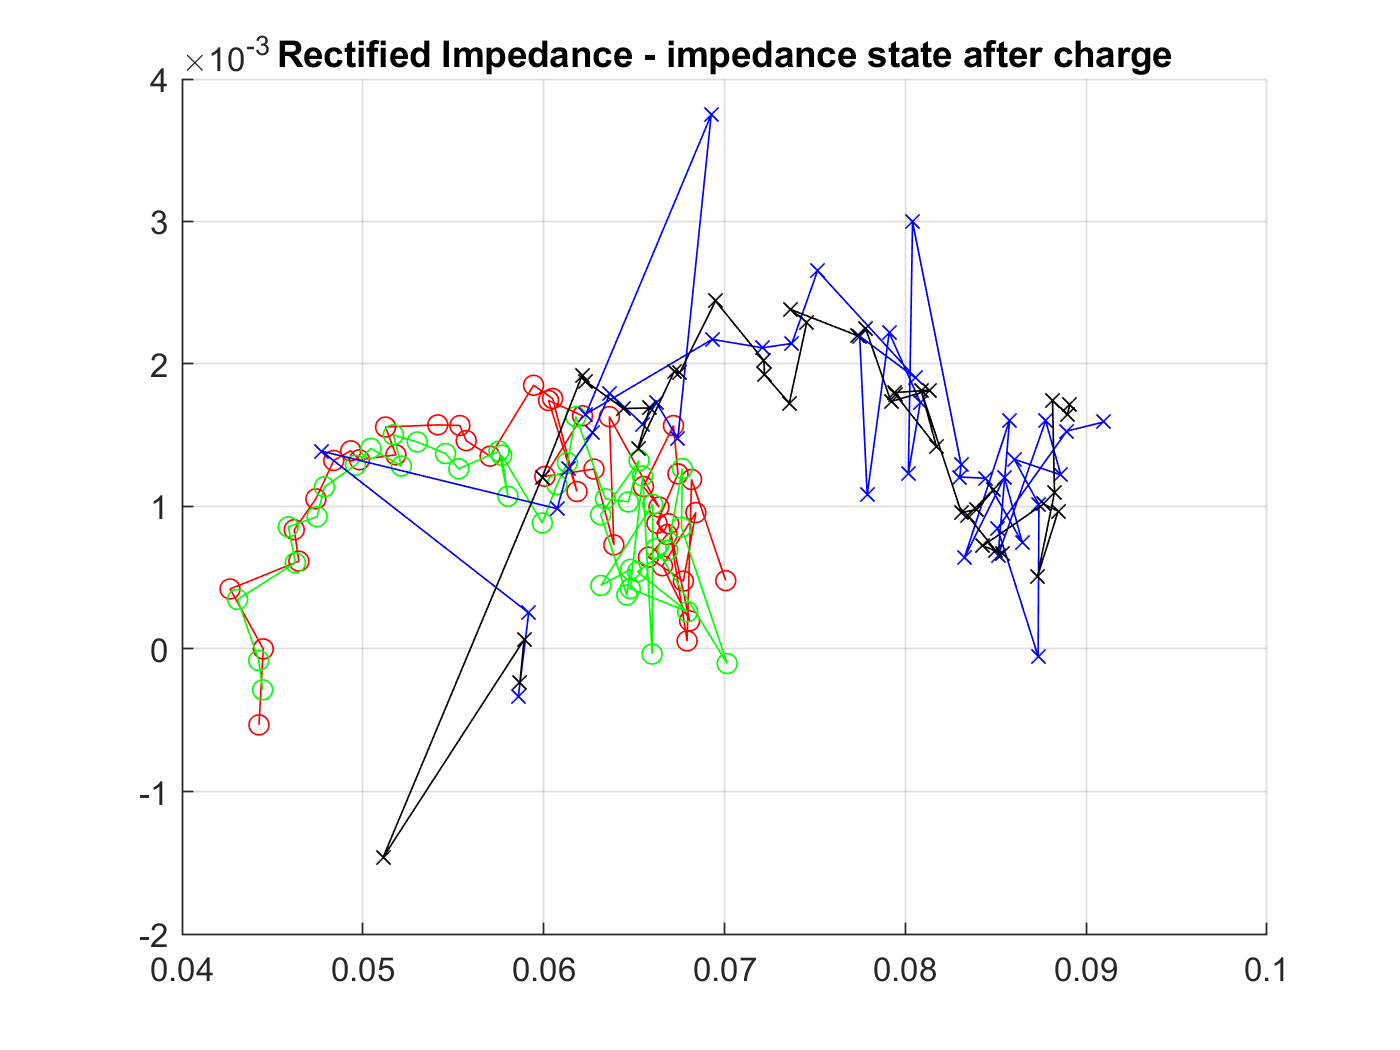



%%% Rectified Impedance
figure 
hold on
% after charge 
plot(B0005.cycle(41).data.Rectified_Impedance','r-o')
plot(B0005.cycle(45).data.Rectified_Impedance','g-o')
plot(B0005.cycle(607).data.Rectified_Impedance','b-x')
plot(B0005.cycle(611).data.Rectified_Impedance','k-x')
hold off
title("Rectified Impedance - impedance state after charge")
grid on

B0005.cycle(43).data.Rectified_Impedance

ans =    0.0604 - 0.0002i
   0.0782 - 0.0016i
   0.0741 - 0.0010i
   0.0737 - 0.0008i
   0.0724 - 0.0014i
   0.0726 - 0.0011i
   0.0731 - 0.0009i
   0.0716 - 0.0013i
   0.0729 - 0.0007i
   0.0708 - 0.0013i


B0005.cycle(43).data.Re

ans = 0.0467

B0005.cycle(43).data.Rct

ans = 0.0763


B0005.cycle(611).data.Rectified_Impedance

ans =    0.0891 - 0.0017i
   0.0889 - 0.0016i
   0.0881 - 0.0017i
   0.0882 - 0.0011i
   0.0873 - 0.0005i
   0.0885 - 0.0010i
   0.0876 - 0.0010i
   0.0843 - 0.0007i
   0.0854 - 0.0007i
   0.0850 - 0.0007i


B0005.cycle(611).data.Re

ans = 0.0578

B0005.cycle(611).data.Rct

ans = 0.0898

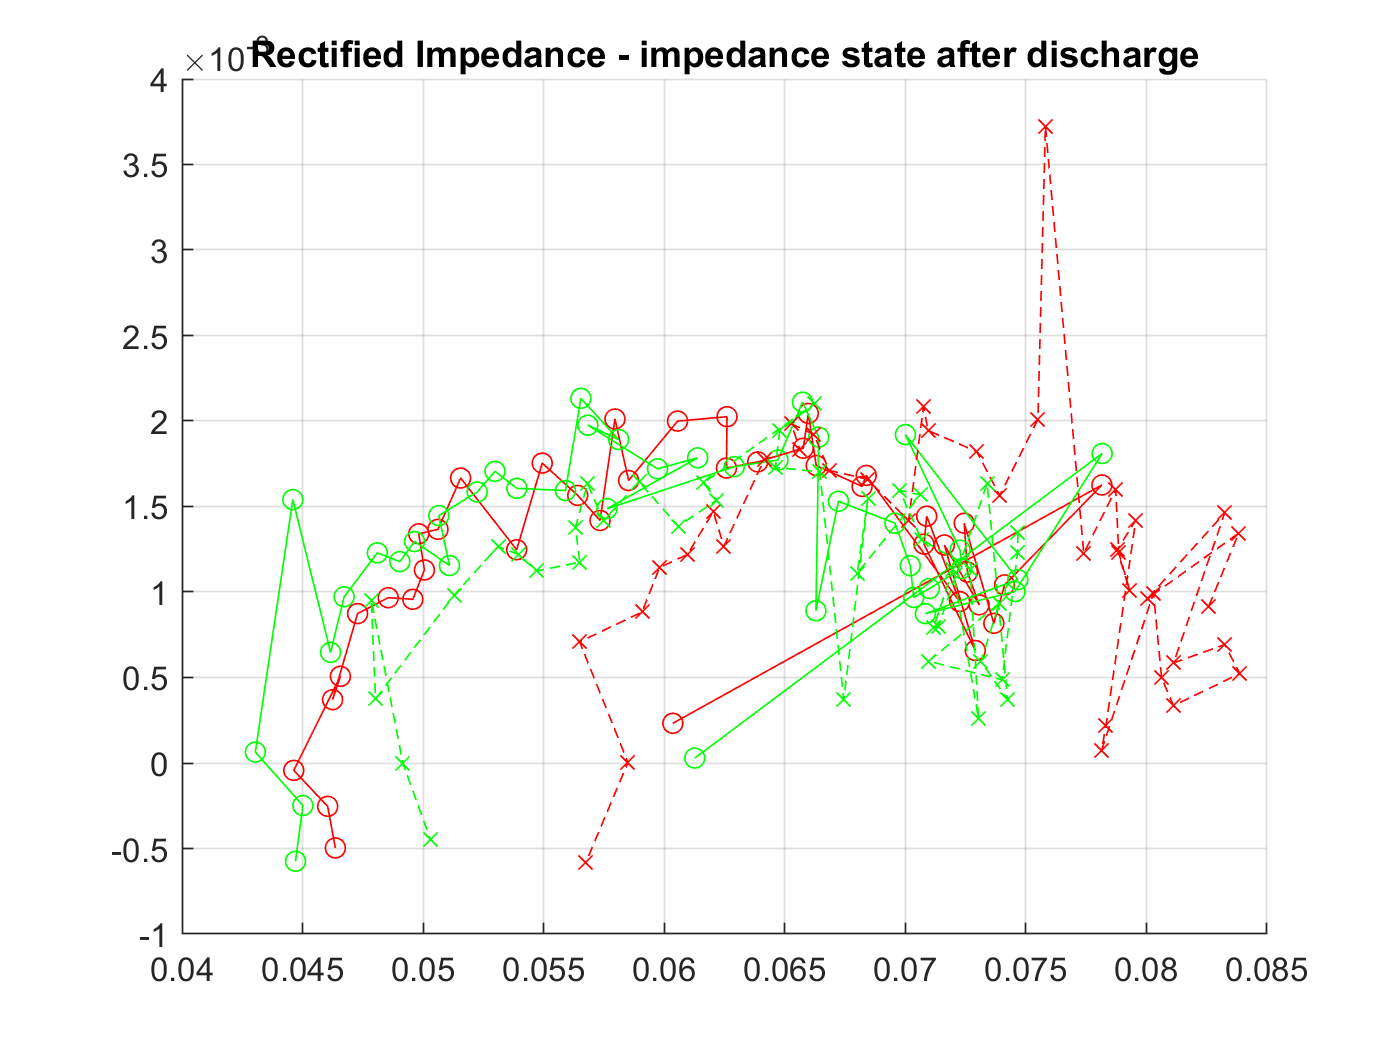


figure 
hold on
% after didscahage 43 47 
plot(B0005.cycle(43).data.Rectified_Impedance','r-o')
plot(B0005.cycle(47).data.Rectified_Impedance','g-o')
plot(B0005.cycle(609).data.Rectified_Impedance','r--x')
plot(B0005.cycle(615).data.Rectified_Impedance','g--x')
hold off
title("Rectified Impedance - impedance state after discharge")
grid on







figure
%newcolors = {'#F00','#F80','#FF0','#0B0','#00F','#50F','#A0F'};
%colororder(newcolors)

hold on
items = size(B0005.cycle,2)

items = 616

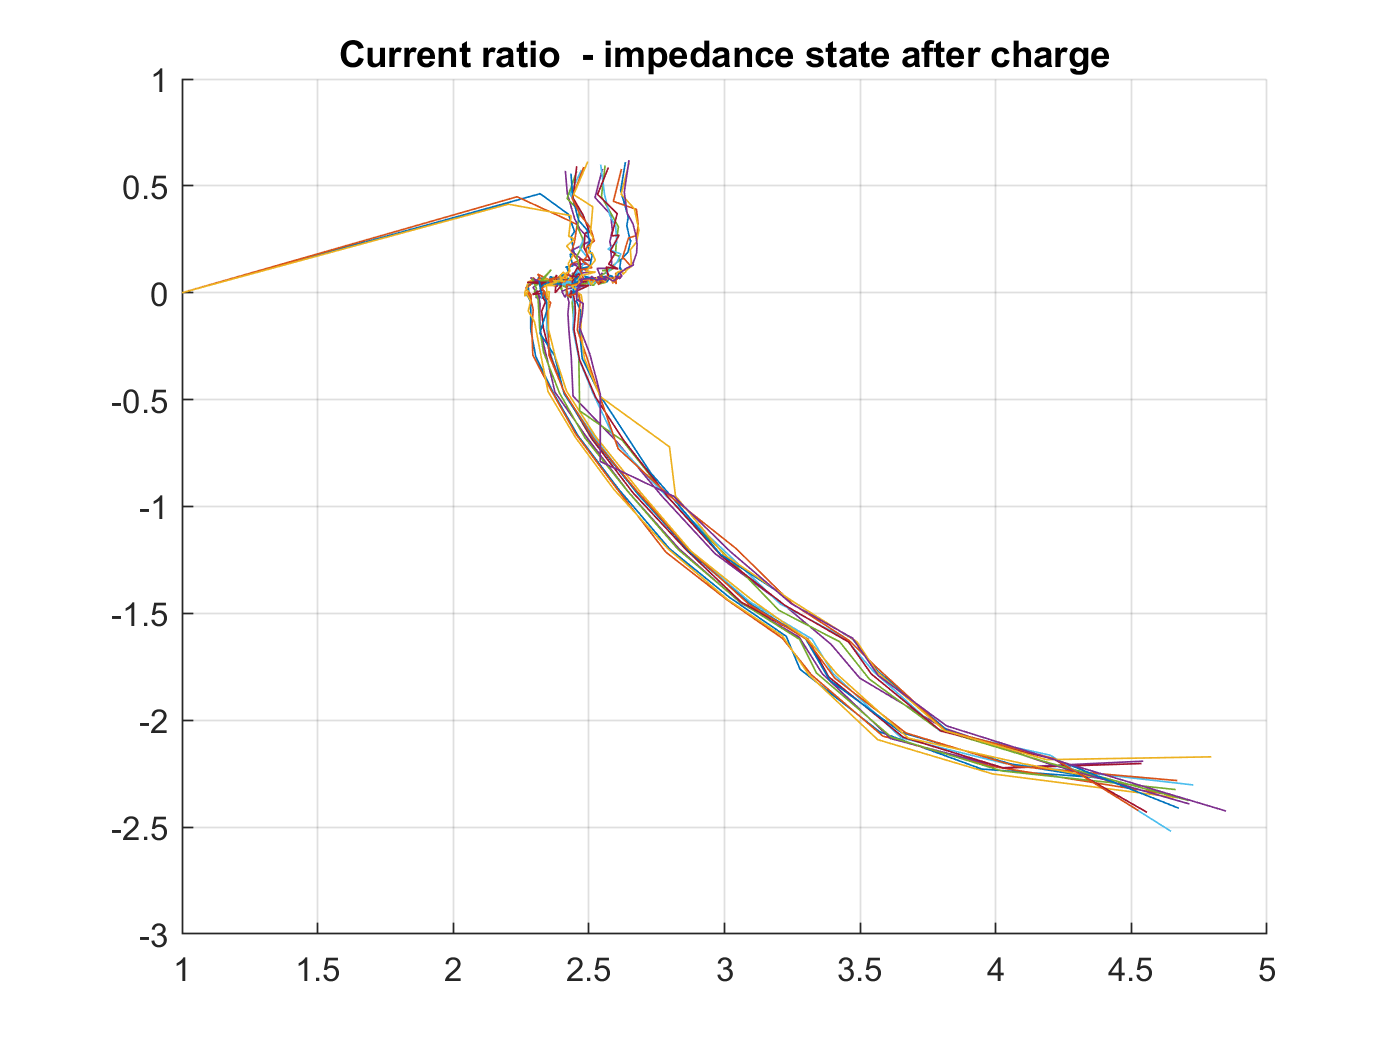

%marker = ['-','--',':','-.','-o','--o',':o','-.o','+',"*"]

line_stype = ['-','--',':', '-.'];
k=1;
for i=1:items
    if isequal(B0005.cycle(i).type, 'impedance')
        if isequal(B0005.cycle(i-1).type, 'charge')
            if mod(i , 10 ) == 1
                 
                %plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Current_ratio)
                plot(B0005.cycle(i).data.Current_ratio,line_stype(k),'MarkerIndices',[1 2 3])
                k = k+1;
                if k == 4 
                    k =1;
                end
                
            end
        end
    end
end
hold off 
title("Current ratio  - impedance state after charge")
grid on

figure
%newcolors = {'#F00','#F80','#FF0','#0B0','#00F','#50F','#A0F'};
%colororder(newcolors)

hold on
items = size(B0005.cycle,2)

items = 616

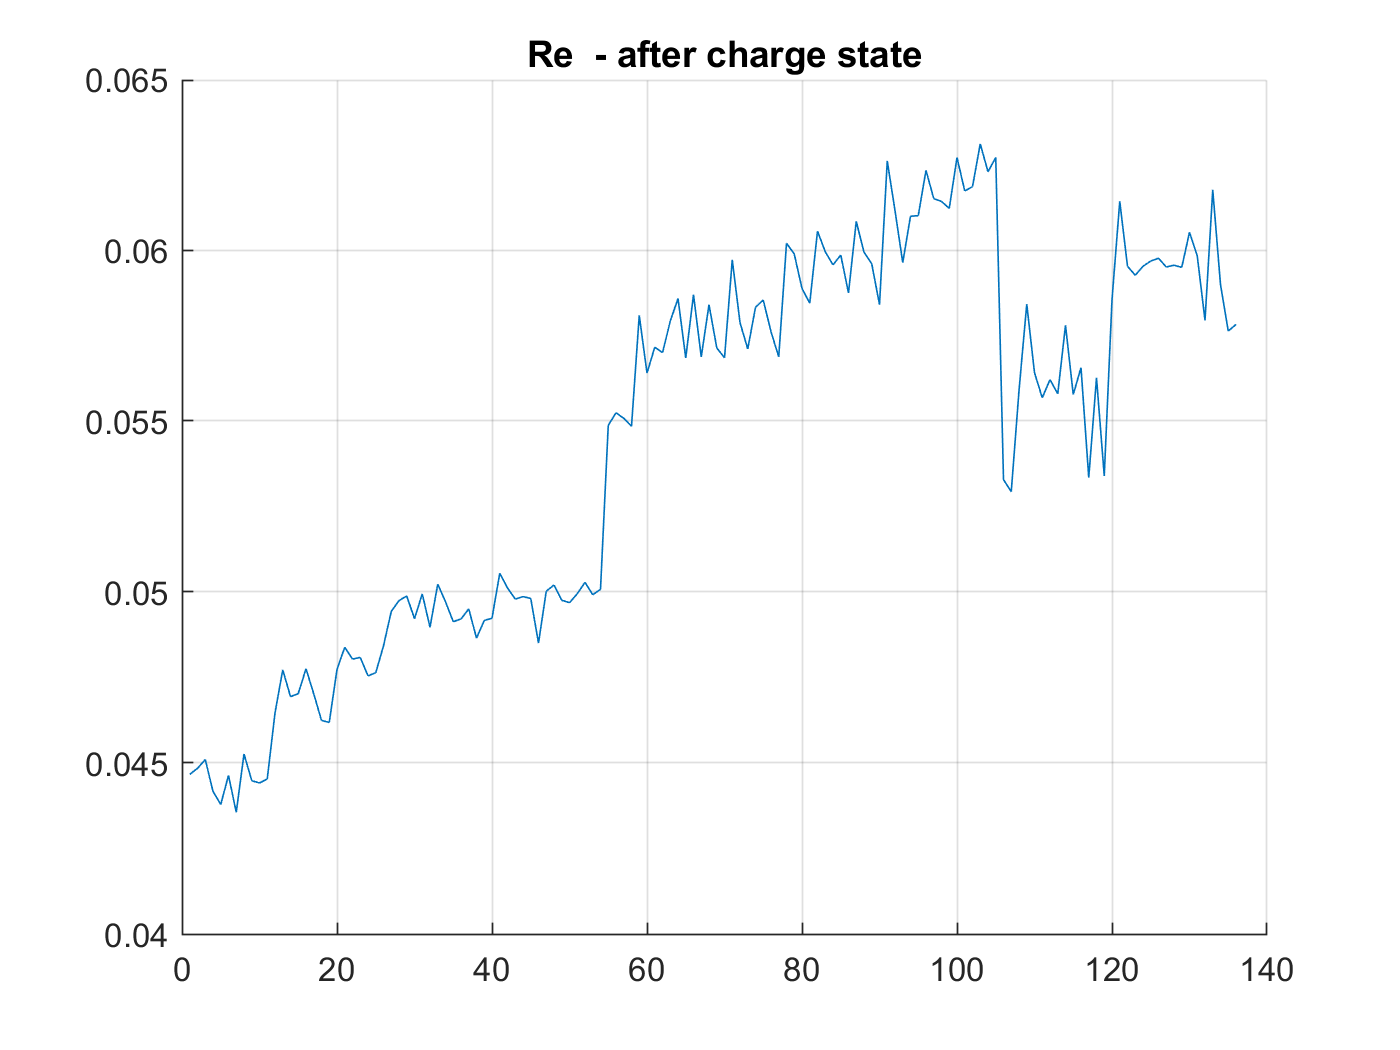

%marker = ['-','--',':','-.','-o','--o',':o','-.o','+',"*"]
Re_table = [];
Rct_table = [];
Time_table = [];
for i=1:items
    if isequal(B0005.cycle(i).type, 'impedance')
         if isequal(B0005.cycle(i-1).type, 'charge')
             Re_table = [Re_table, B0005.cycle(i).data.Re ];
             Rct_table = [Rct_table, B0005.cycle(i).data.Rct ];
             Time_table = [Time_table ,B0005.cycle(i).time ];
            %if mod(i , 10 ) == 1
            %    k = mod (round(i / 10), 10 ) + 1;
            %    plot(B0005.cycle(i).data.Re)
            %end
         end
    end
end
plot(Re_table)

hold off 
title("Re  - after charge state")
grid on

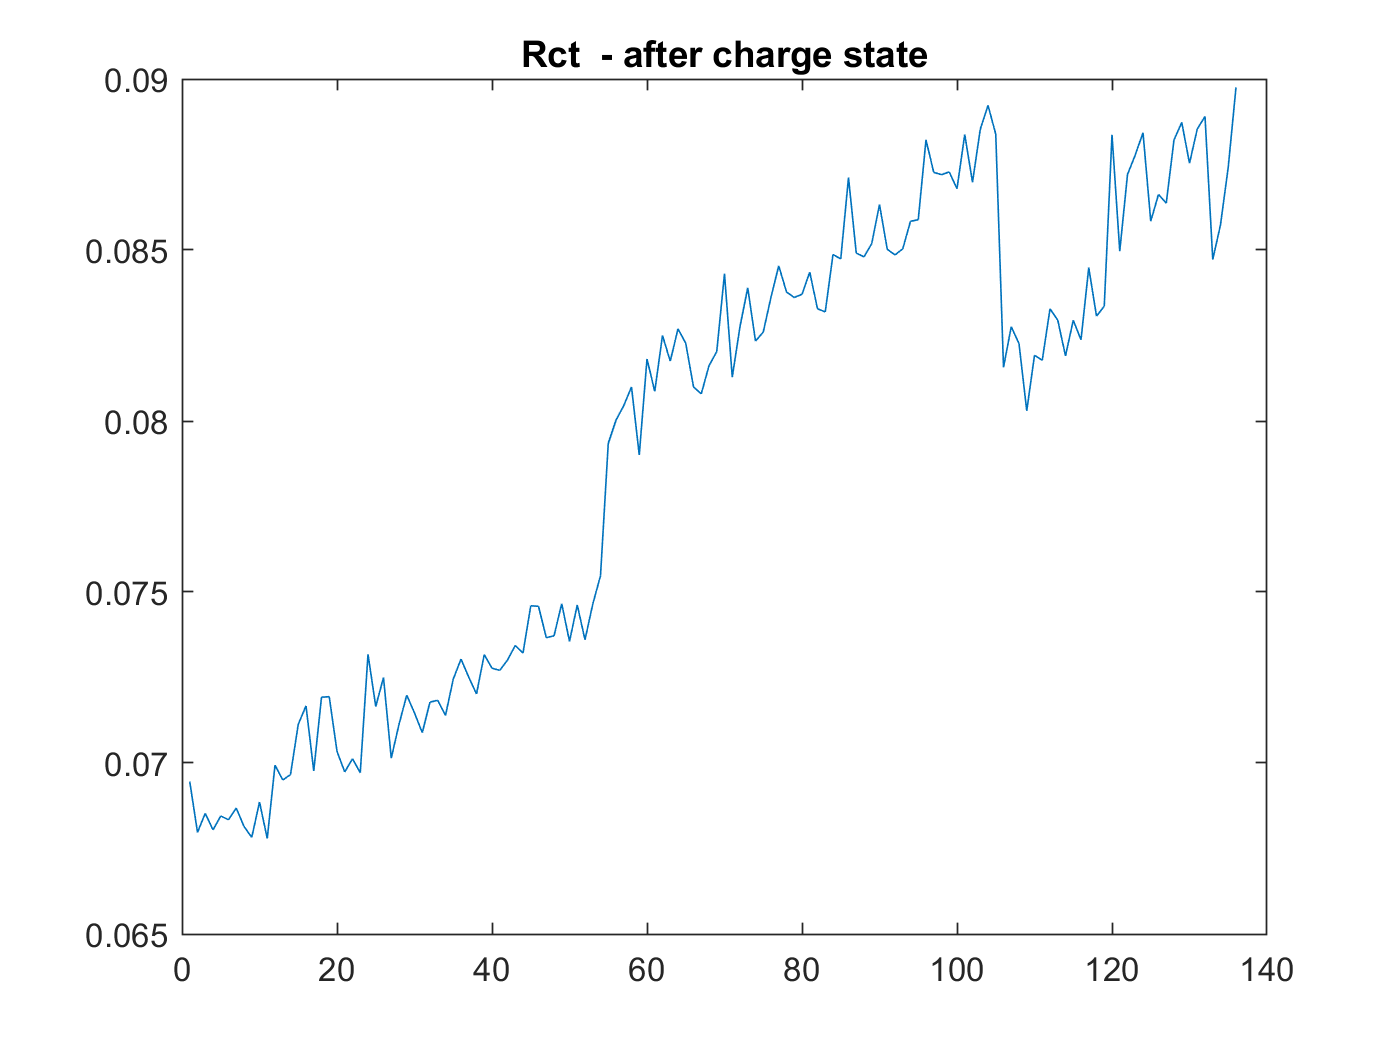

%figure
%plot(Time_table,Re_table)


figure 
plot(Rct_table)

title("Rct  - after charge state")

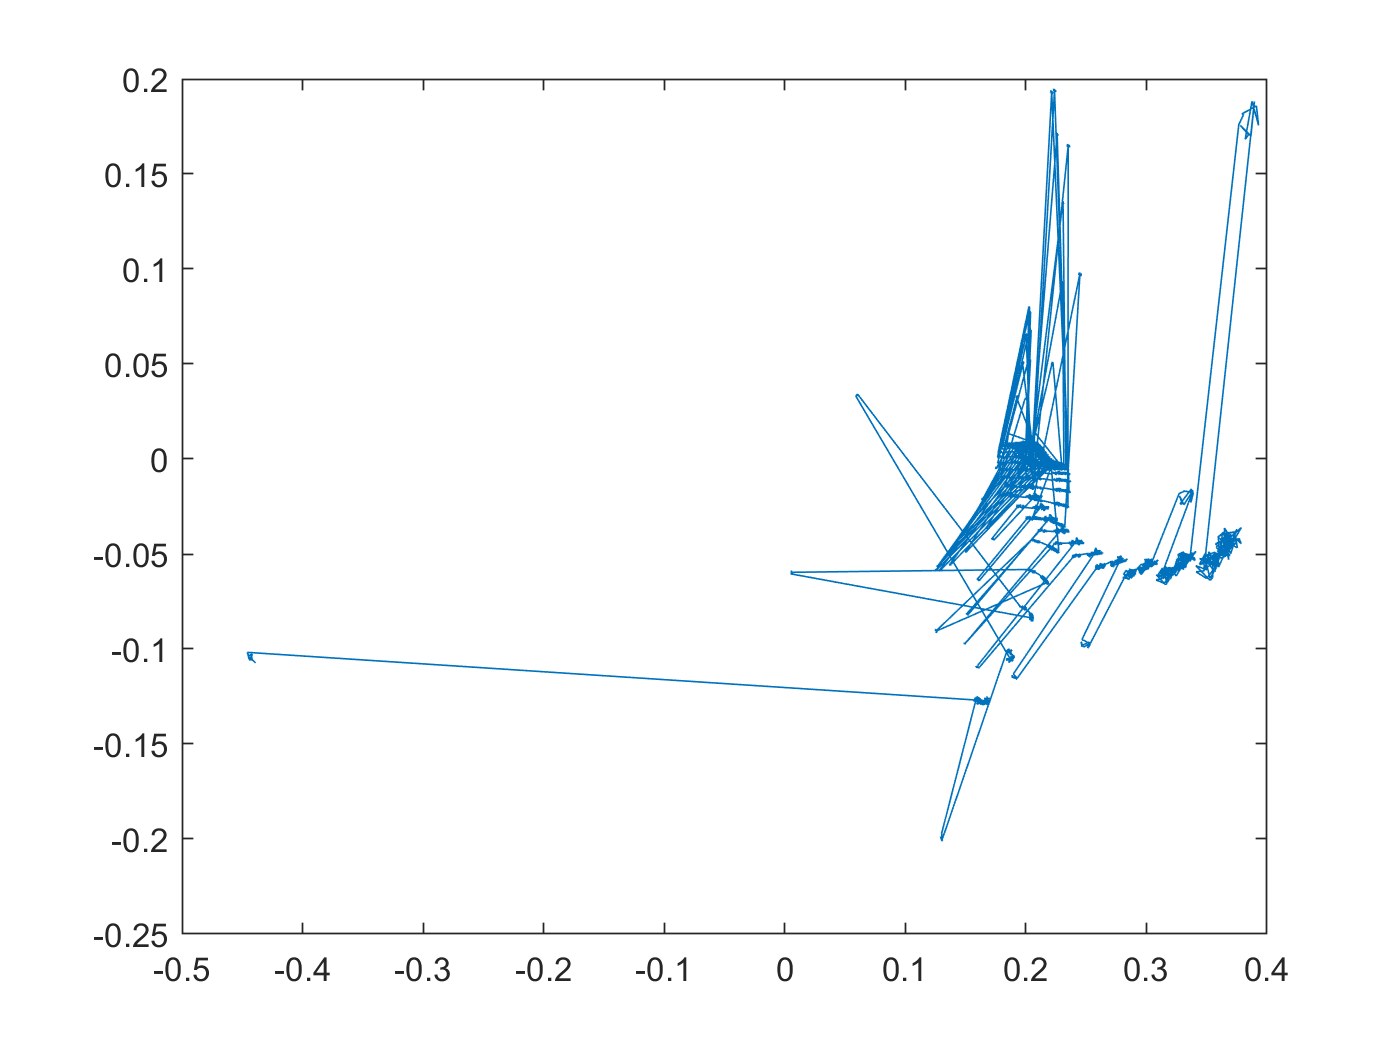



%%%%%%% Impedance

% find first Battery_impedance
imp = [];
for i = 1:length(B0005.cycle)
    if isequal(B0005.cycle(i).type, 'impedance')
        if isequal(B0005.cycle(i-1).type, 'charge')
            imp(i,:) = B0005.cycle(i).data.Battery_impedance;
            imp_rect(i,:) = transpose( B0005.cycle(i).data.Rectified_Impedance);
        end
    end
end
imp(imp==0) = [];
imp_rect(imp_rect==0) = [];


figure
plot(imp) 

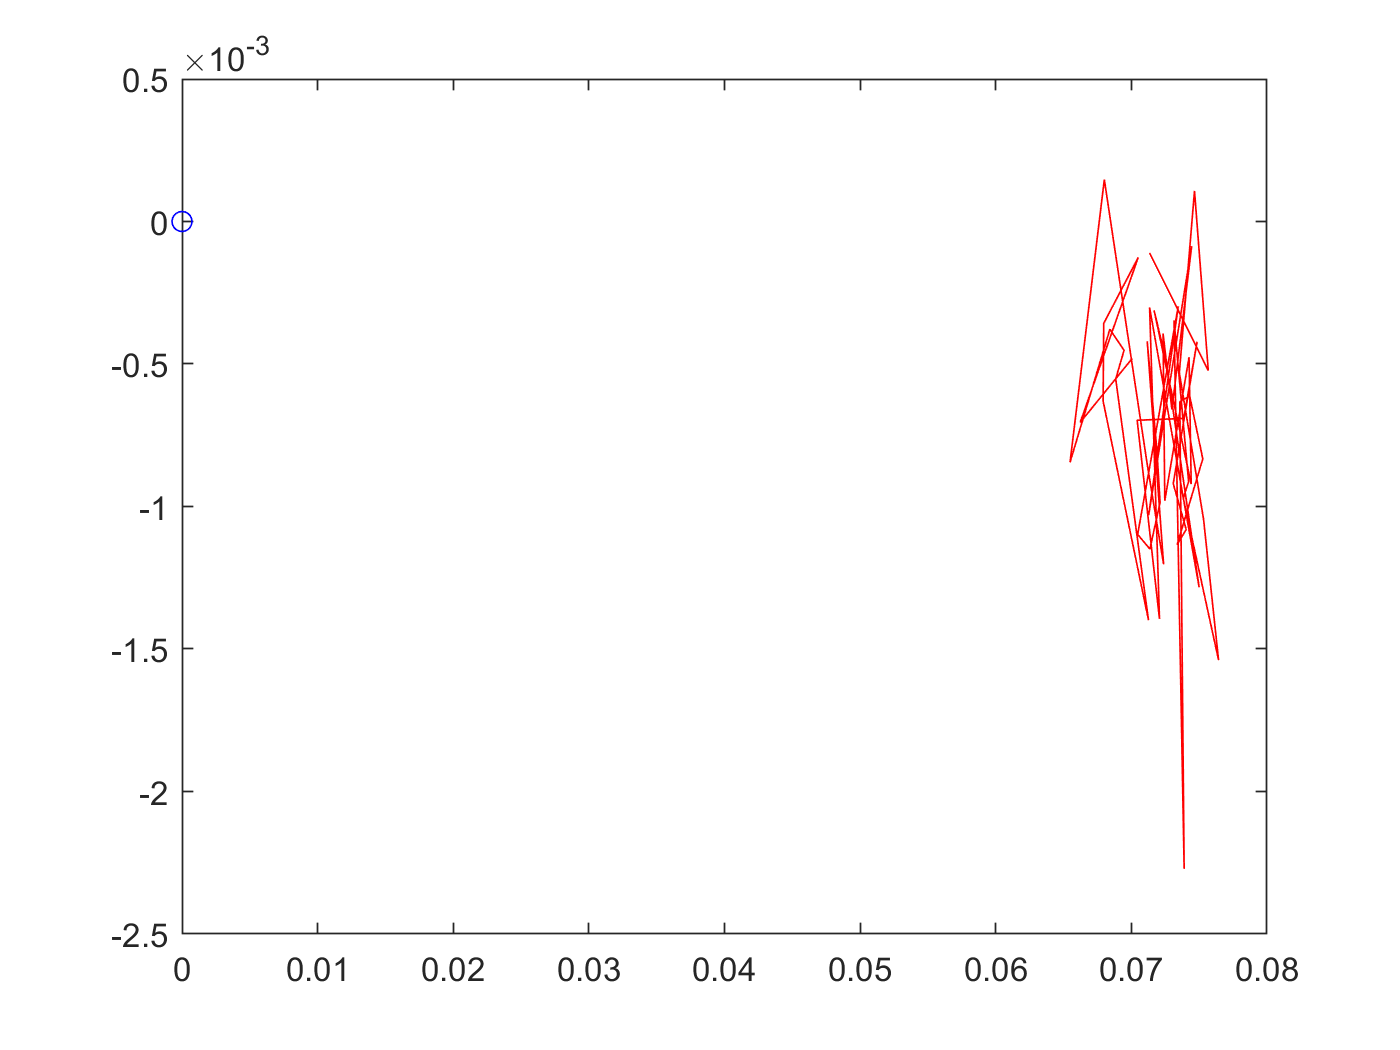

figure
plot(0,0,'bo',real(imp_rect(1:50)),imag(imp_rect(1:50)),'r')

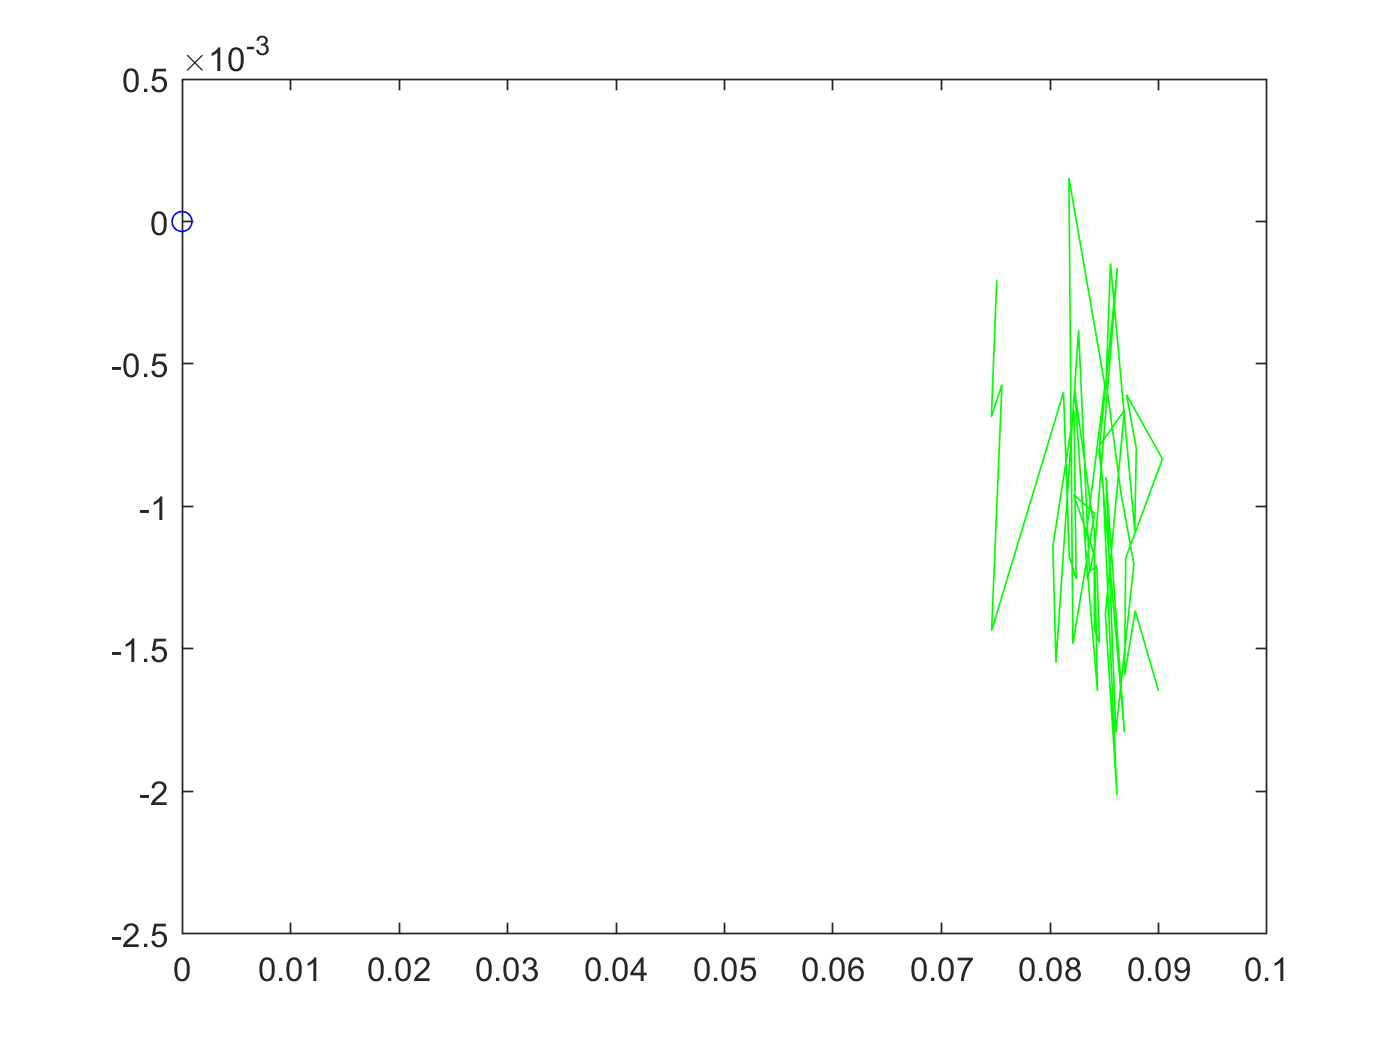

figure
plot(0,0,'bo',real(imp_rect(51:100)),imag(imp_rect(51:100)),'g')

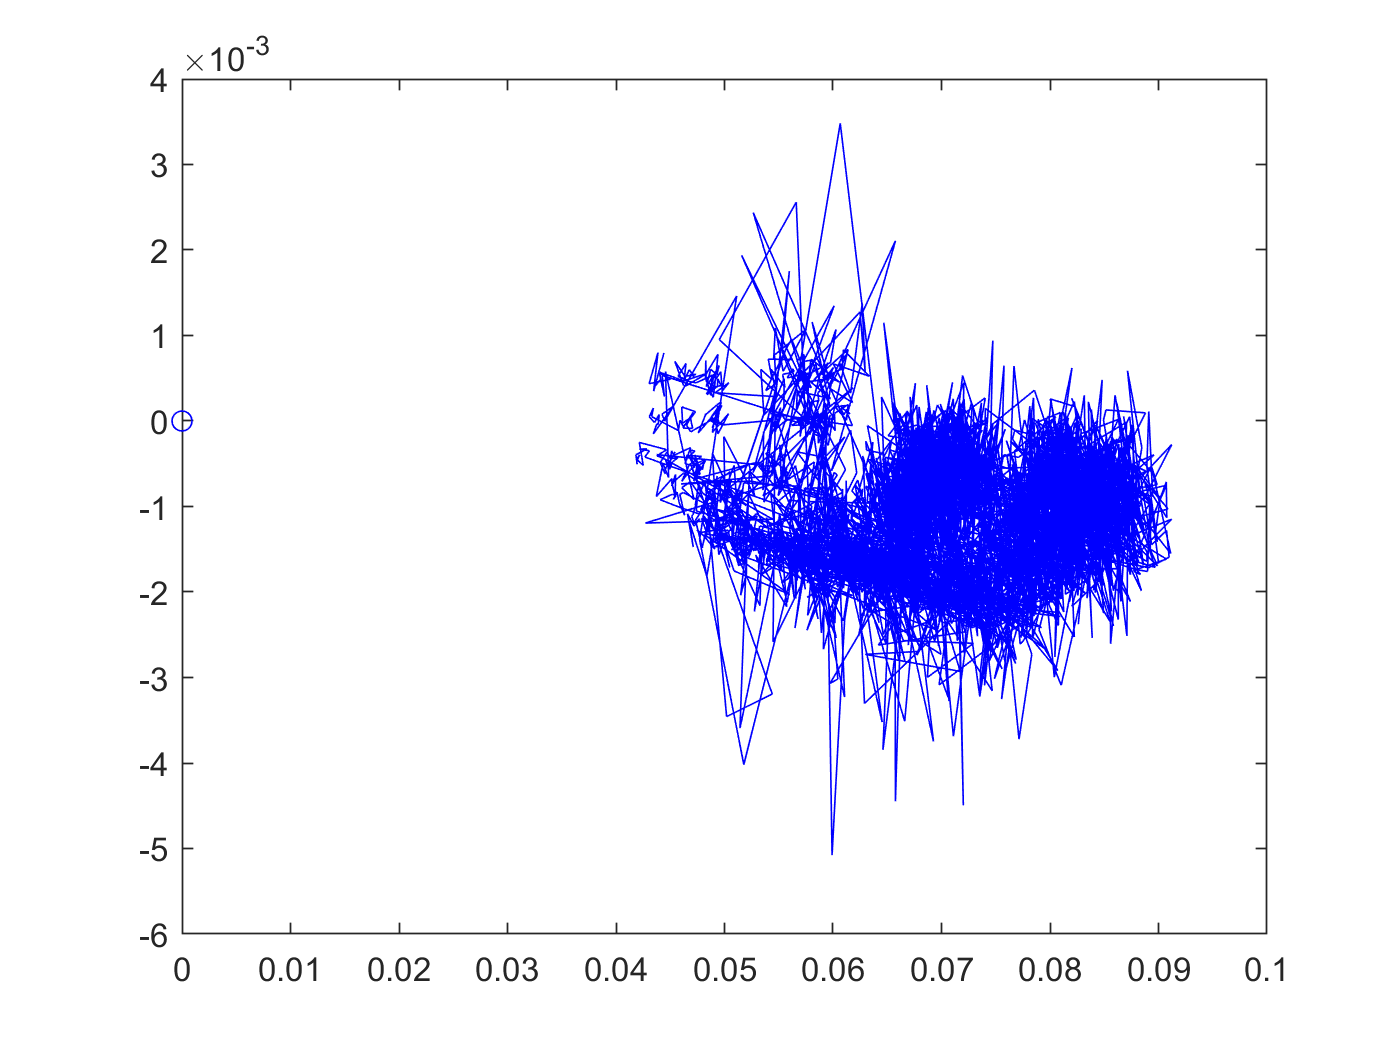

figure
plot(0,0,'bo',real(imp_rect(100:end)),imag(imp_rect(100:end)),'b')

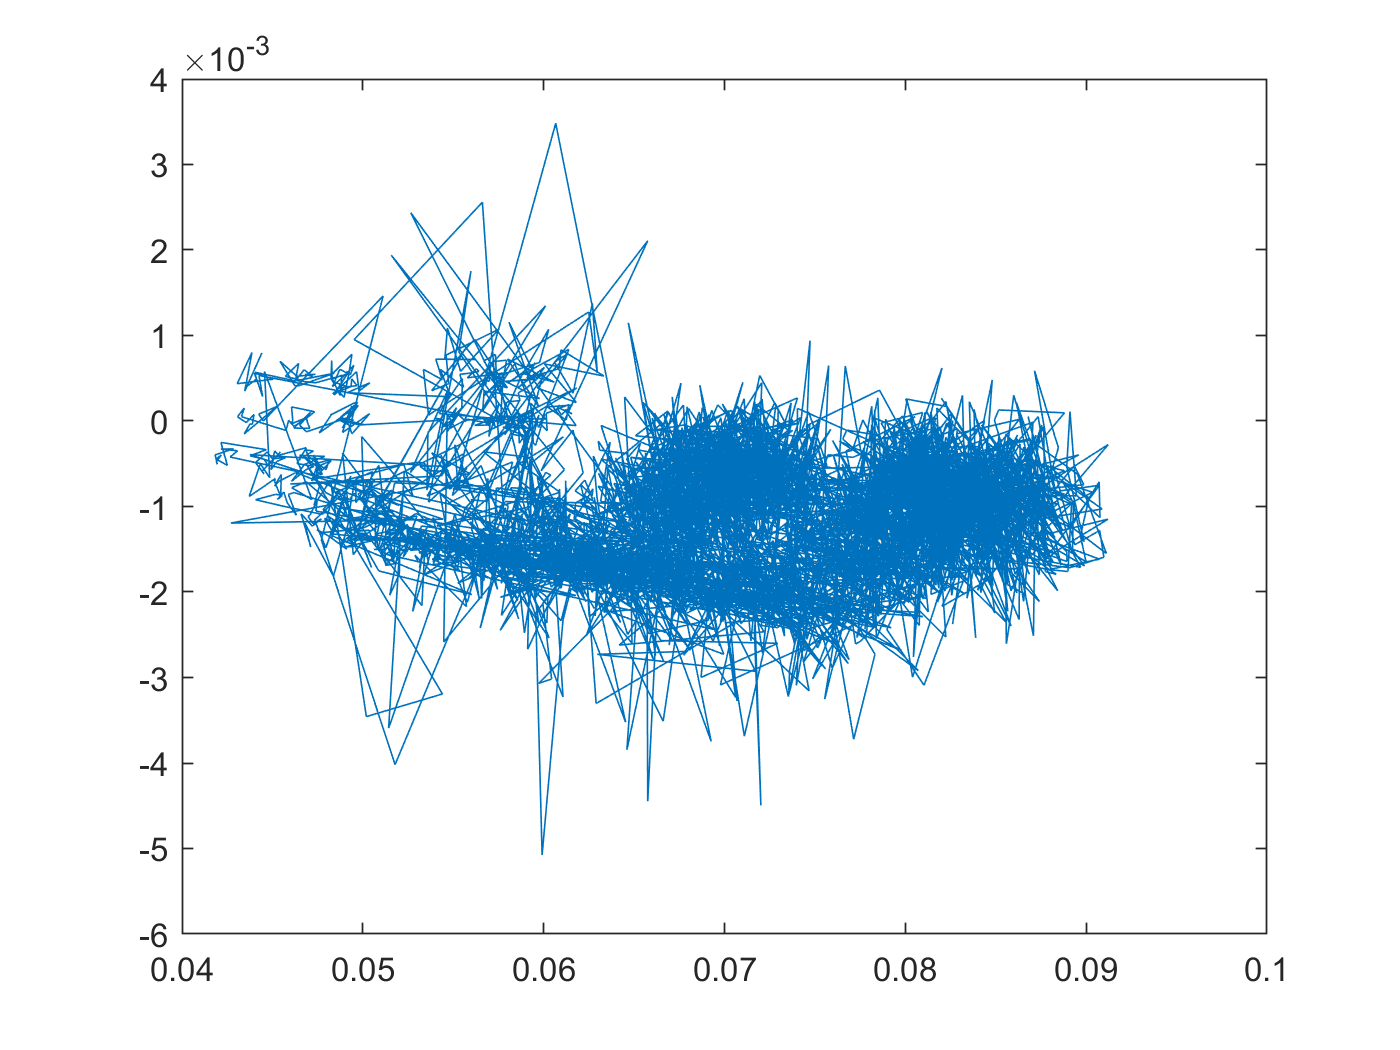


%axis([-0.01 0.1 -0.02 0.02])
%colormap(ax2,jet)
%axis square

figure
plot(imp_rect)

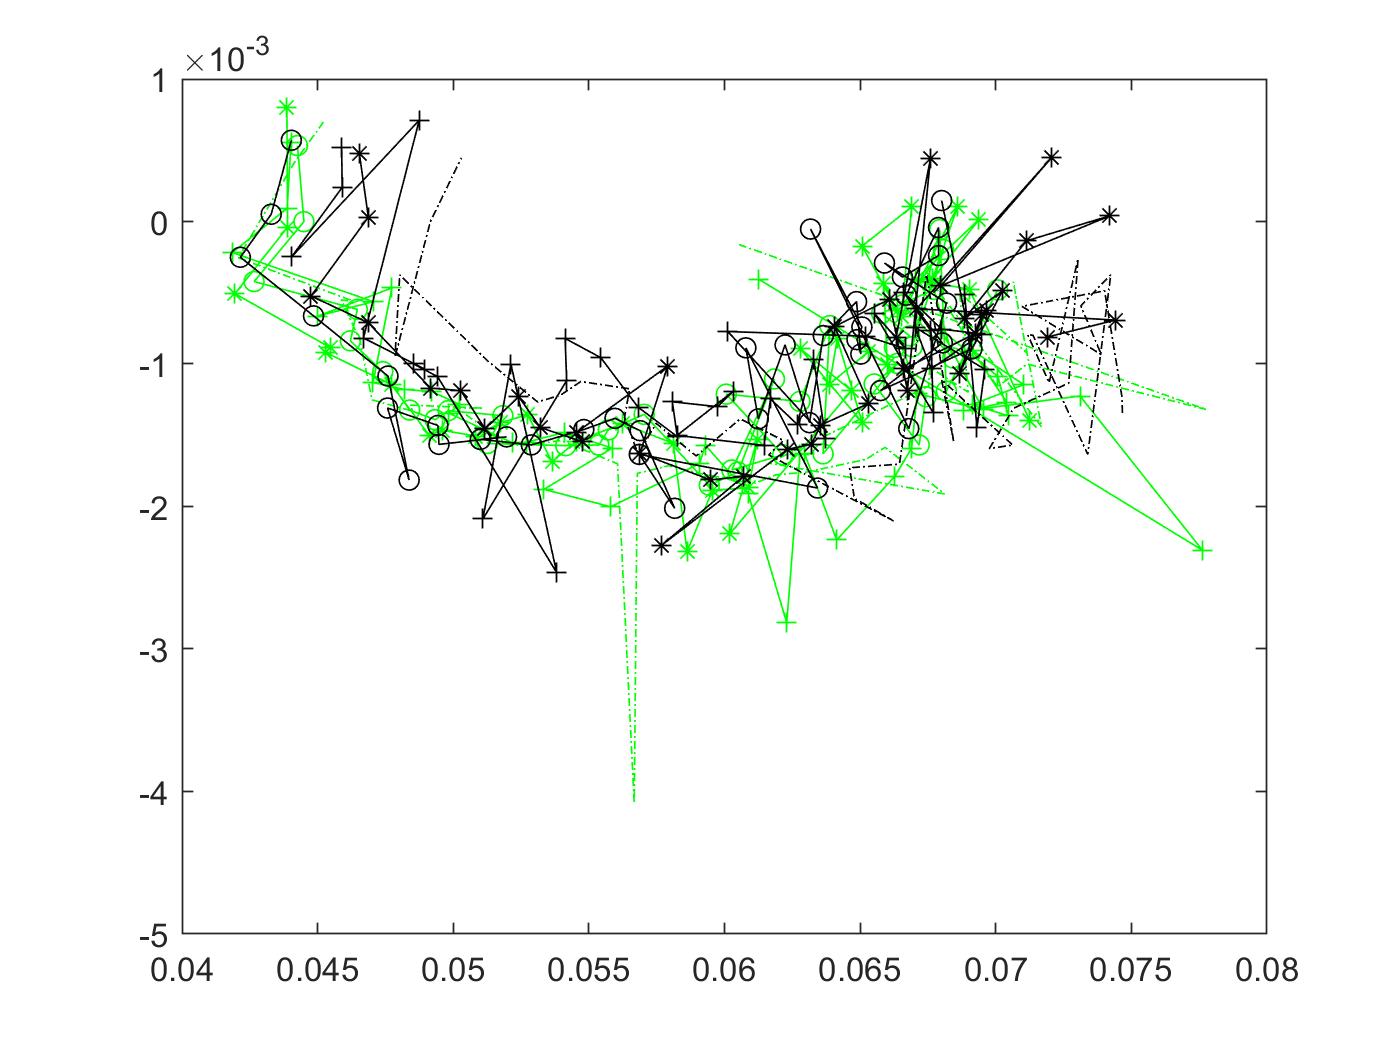



data = B0005.cycle(41).data.Battery_impedance;
data1 = B0005.cycle(51).data.Battery_impedance;
data2 = B0005.cycle(61).data.Battery_impedance;
data3 = B0005.cycle(71).data.Battery_impedance;
data4 = B0005.cycle(81).data.Battery_impedance;
data5 = B0005.cycle(91).data.Battery_impedance;
data6 = B0005.cycle(101).data.Battery_impedance;
data7 = B0005.cycle(615).data.Battery_impedance;

rdata = B0005.cycle(41).data.Rectified_Impedance;
rdata1 = B0005.cycle(51).data.Rectified_Impedance;
rdata2 = B0005.cycle(61).data.Rectified_Impedance;
rdata3 = B0005.cycle(71).data.Rectified_Impedance;
rdata4 = B0005.cycle(81).data.Rectified_Impedance;
rdata5 = B0005.cycle(91).data.Rectified_Impedance;
rdata6 = B0005.cycle(101).data.Rectified_Impedance;
rdata7 = B0005.cycle(615).data.Rectified_Impedance;

data_re = real(data);
data_im = imag(data);

figure
plot(rdata,'g-o') 
hold on, 
plot(rdata,'g-o'),plot(rdata1,'g-+'), plot(rdata2,'g-*'),plot(rdata3,'g-.'),
plot(rdata4,'k-o'),plot(rdata5,'k-+'), plot(rdata6,'k-*'),plot(rdata7,'k-.'),

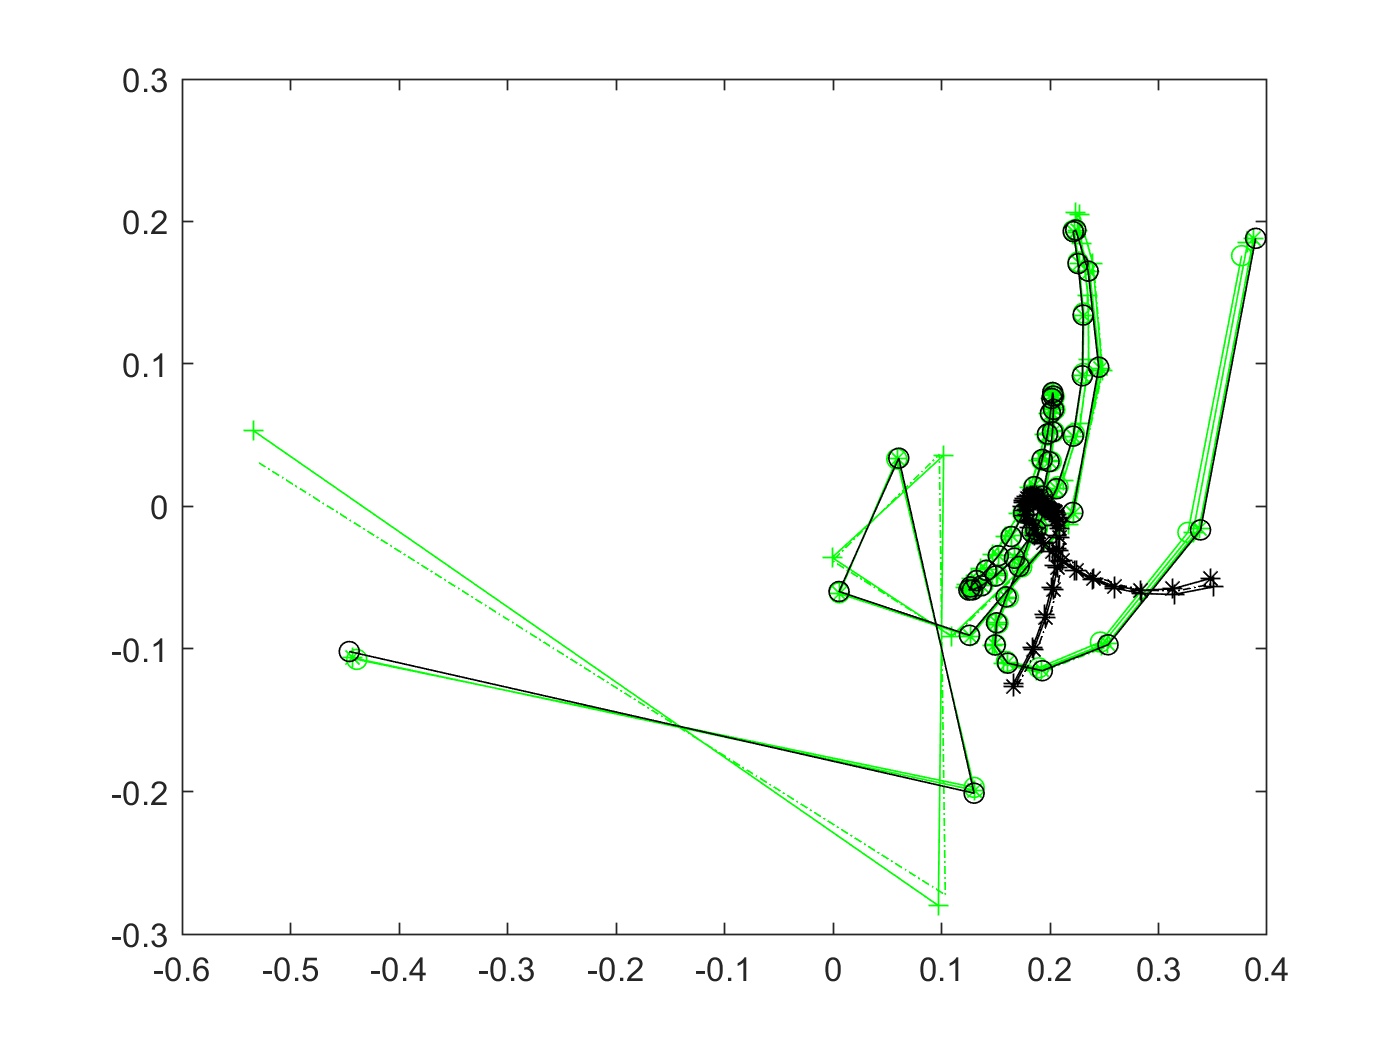


figure
plot(data,'g-o') 
hold on, 
plot(data,'g-o'),plot(data1,'g-+'), plot(data2,'g-*'),plot(data3,'g-.'),
plot(data4,'k-o'),plot(data5,'k-+'), plot(data6,'k-*'),plot(data7,'k-.'),

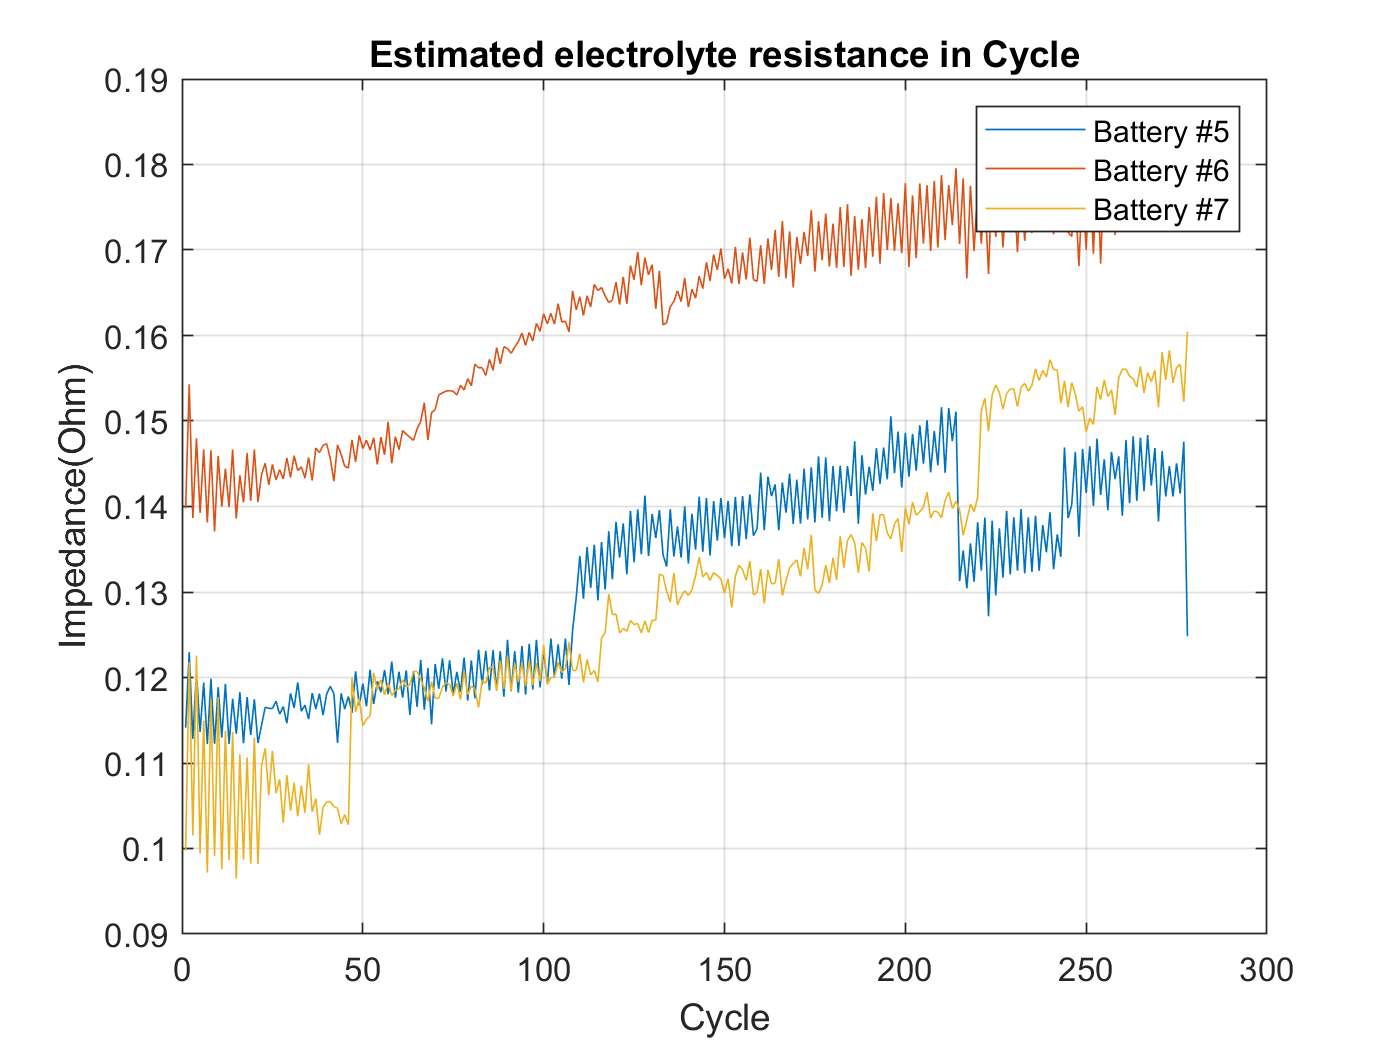

%%%%%%% Impedance 

re5 = extract_impedance(B0005);
re6 = extract_impedance(B0006);
re7 = extract_impedance(B0007);
figure
plot(re5), hold on, plot(re6), plot(re7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Cycle')

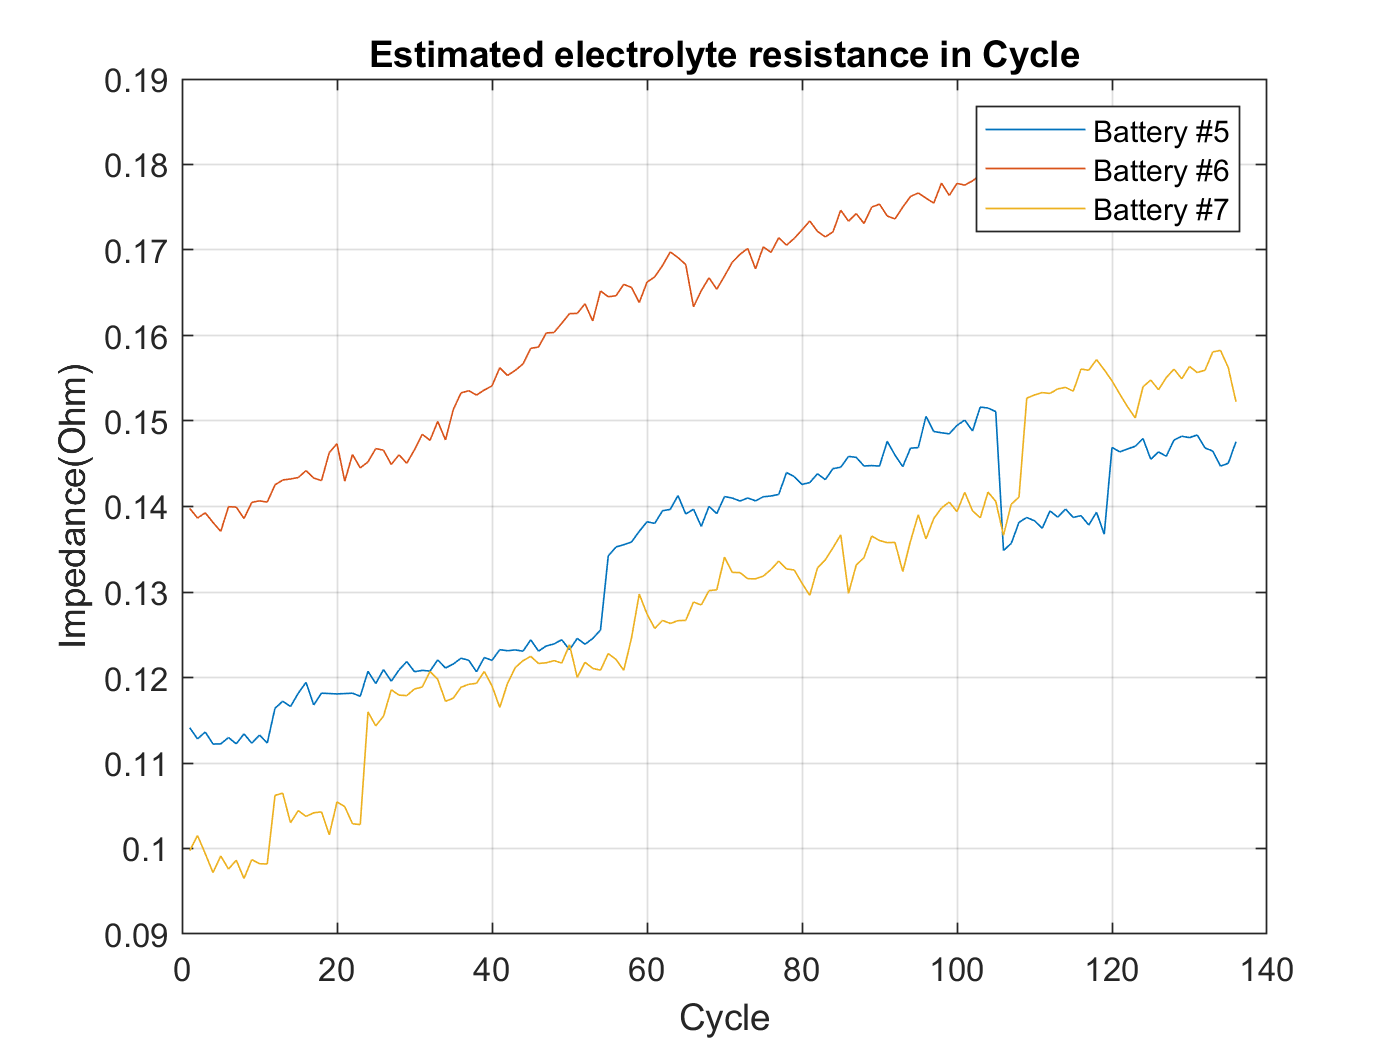



%%%%%%% Impedance - charge
re5 = extract_impedance_charge(B0005);
re6 = extract_impedance_charge(B0006);
re7 = extract_impedance_charge(B0007);
figure
plot(re5), hold on, plot(re6), plot(re7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Cycle')

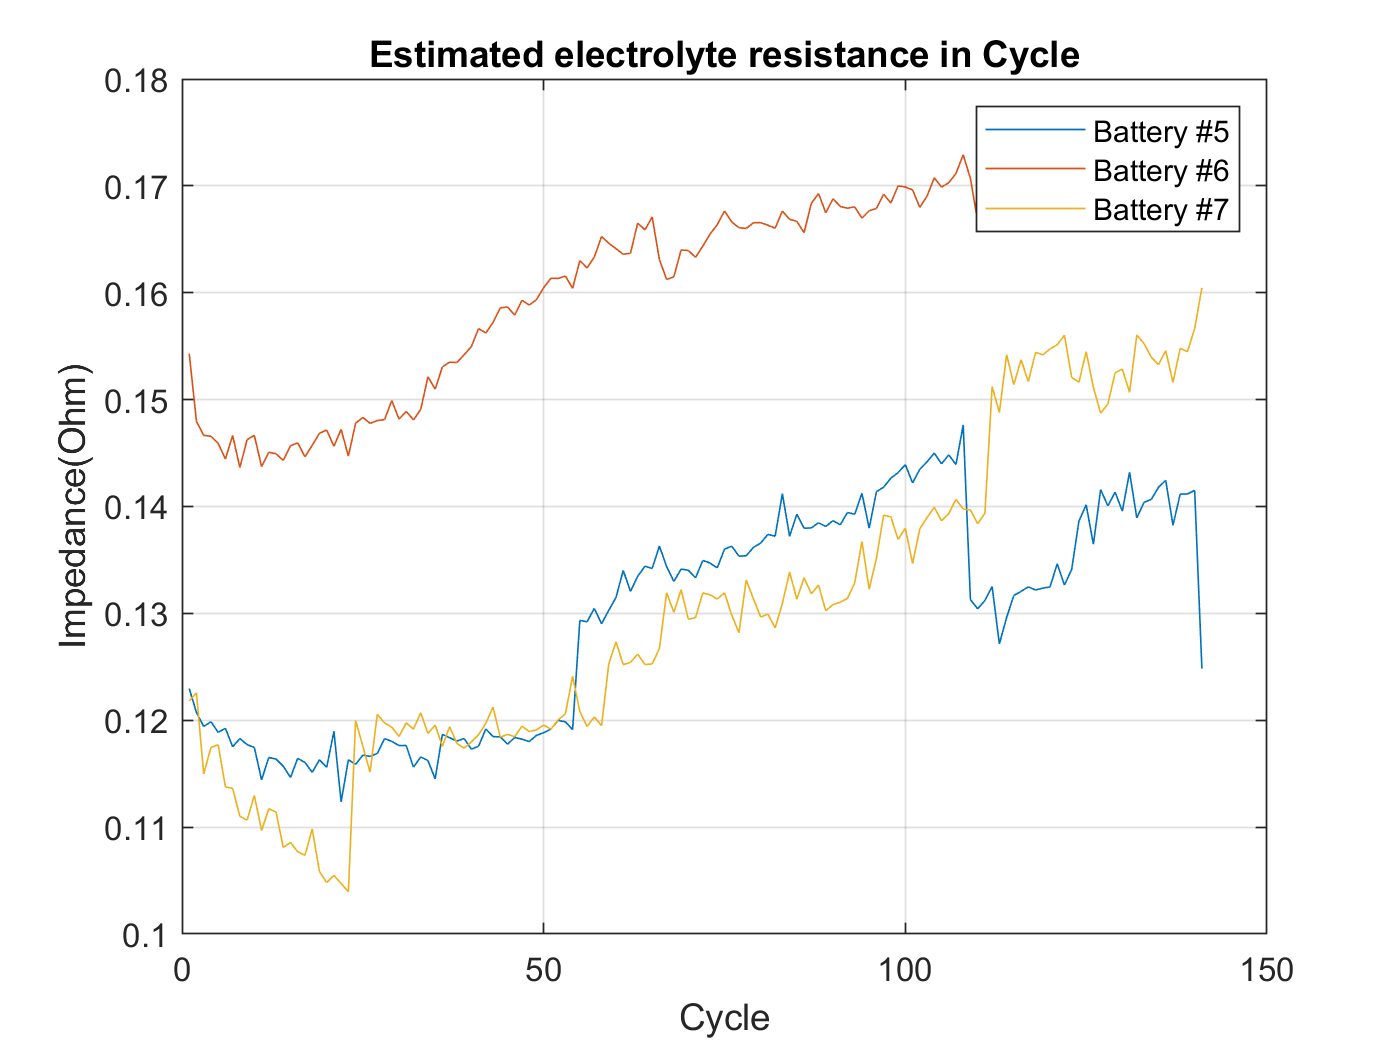



%%%%%%% Impedance - discharge

re5 = extract_impedance_discharge(B0005);
re6 = extract_impedance_discharge(B0006);
re7 = extract_impedance_discharge(B0007);
figure
plot(re5), hold on, plot(re6), plot(re7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Cycle')

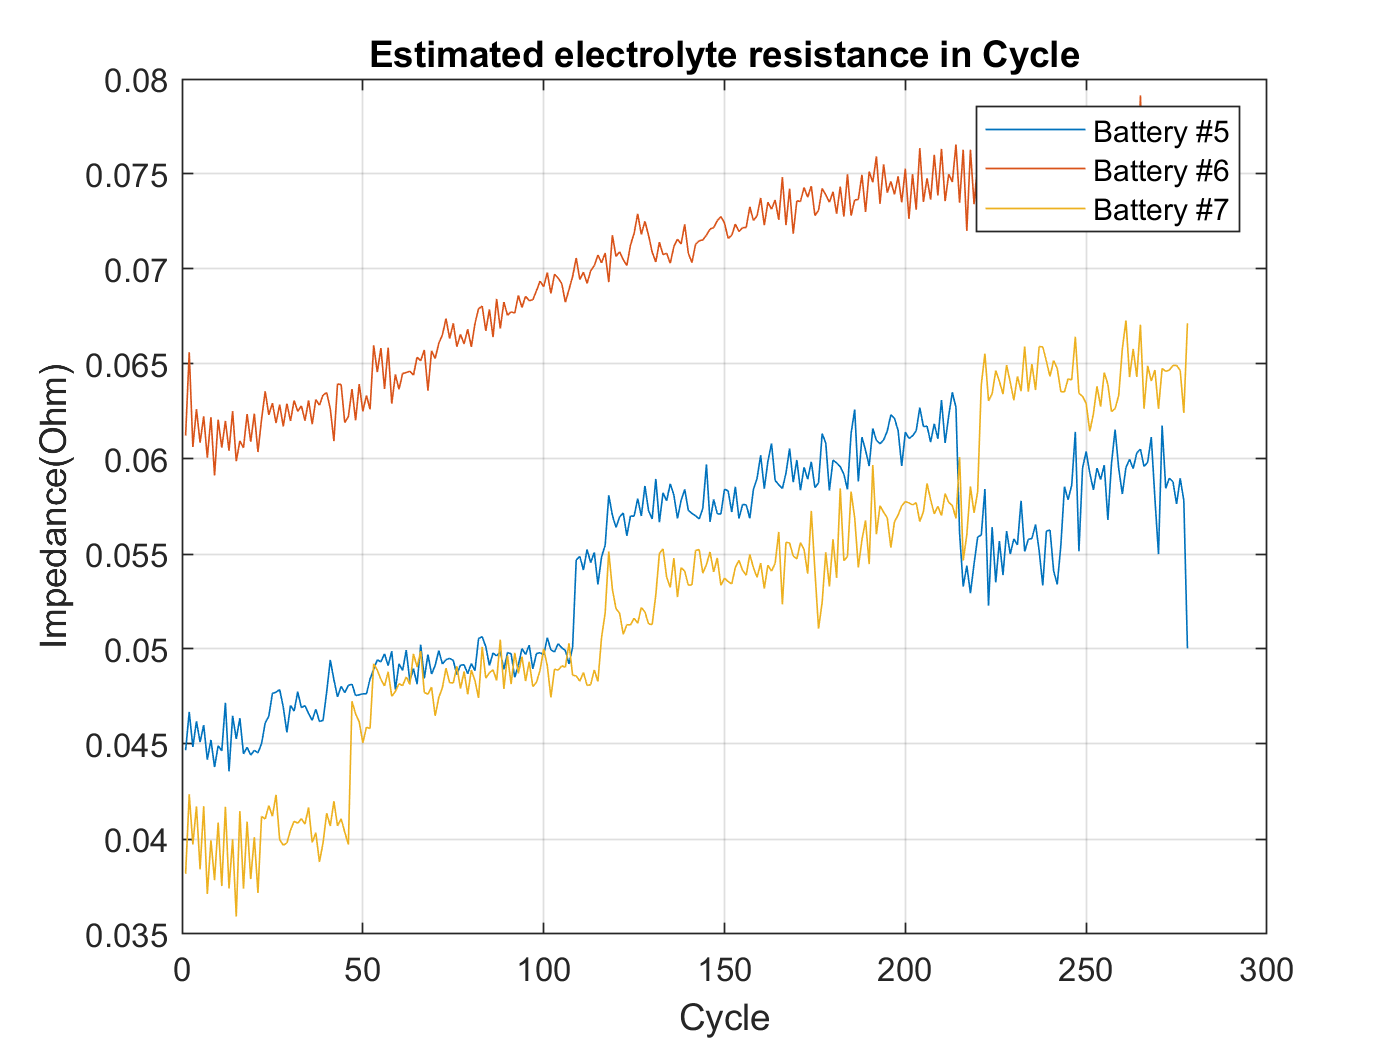





%%%%%%% Re 

re5 = extract_impedance_re(B0005);
re6 = extract_impedance_re(B0006);
re7 = extract_impedance_re(B0007);
figure
plot(re5), hold on, plot(re6), plot(re7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Cycle')

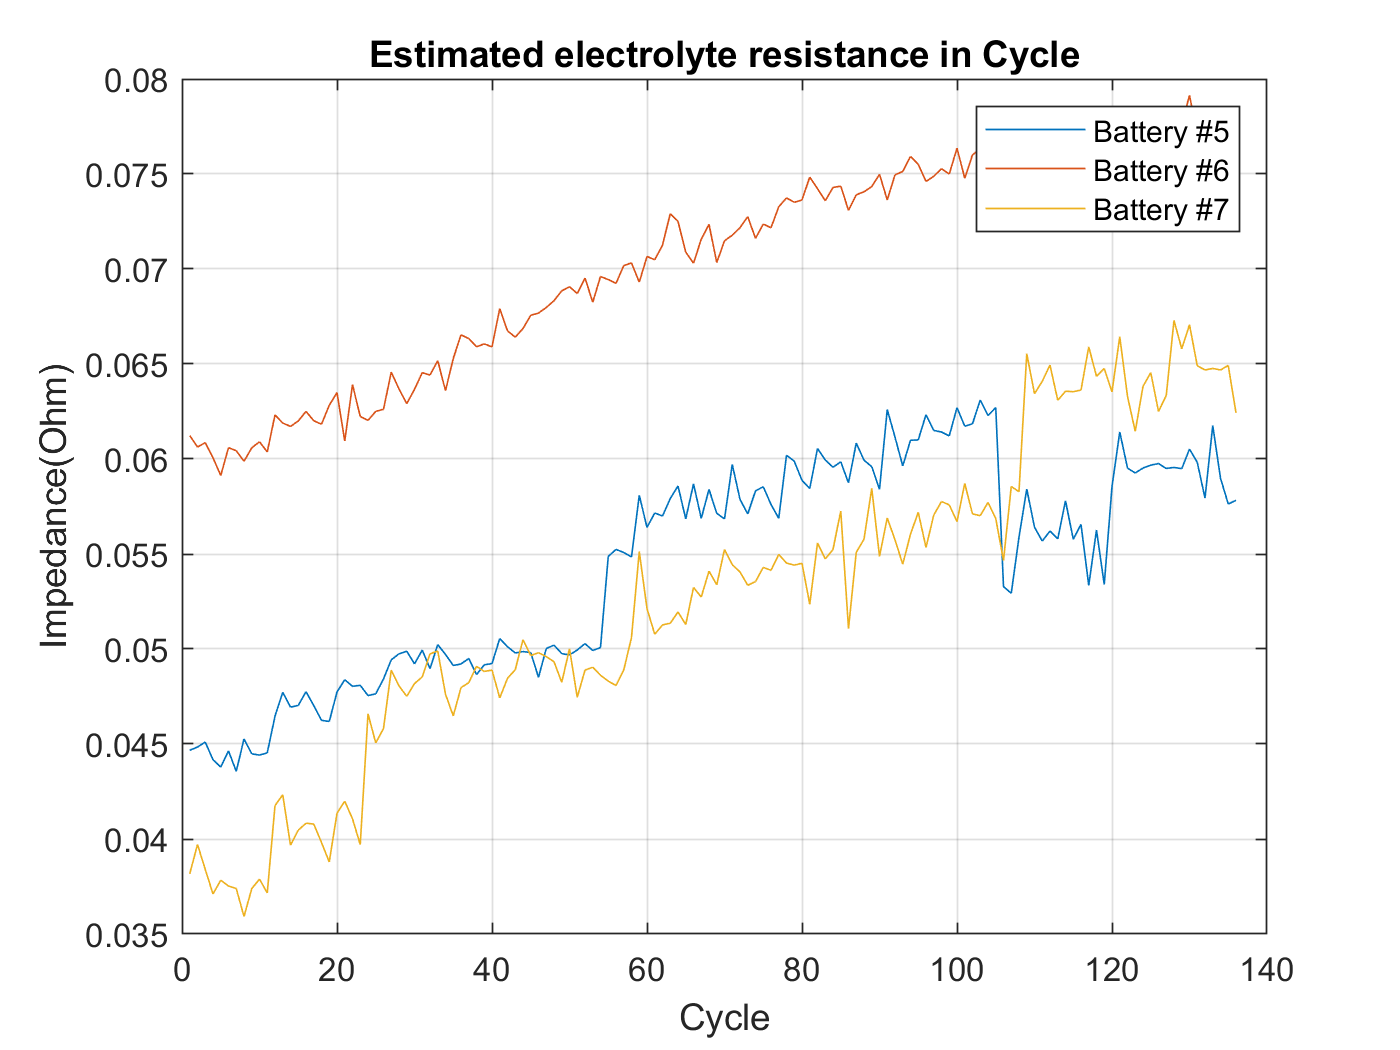



%%%%%%% Re - charge
re5 = extract_impedance_re_charge(B0005);
re6 = extract_impedance_re_charge(B0006);
re7 = extract_impedance_re_charge(B0007);
figure
plot(re5), hold on, plot(re6), plot(re7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Cycle')

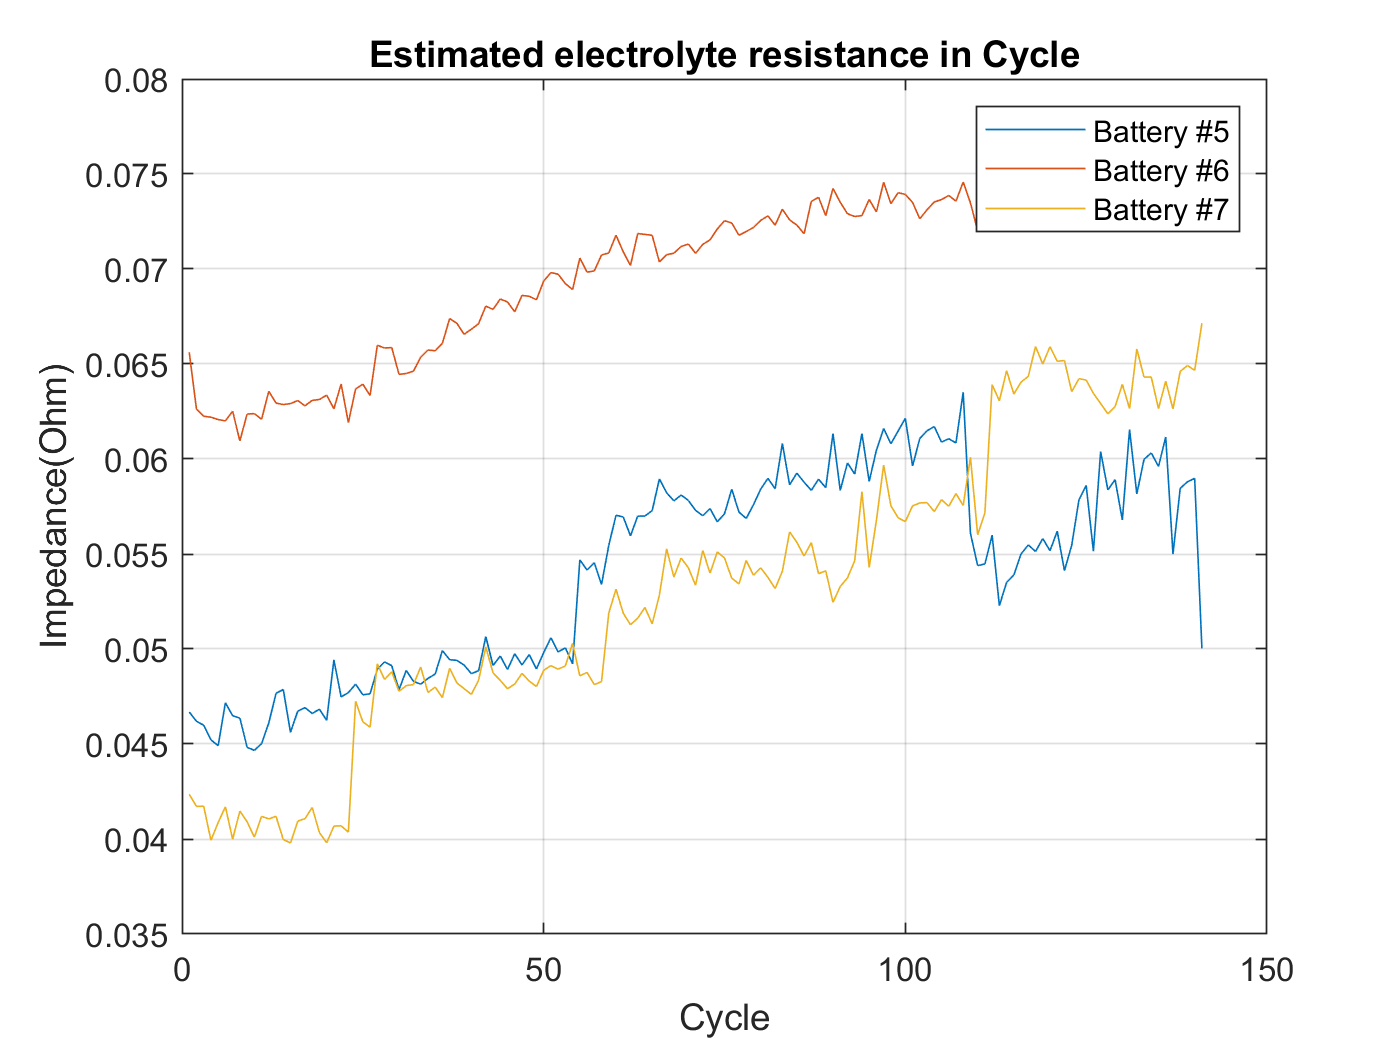



%%%%%%% Re - discharge

re5 = extract_impedance_re_discharge(B0005);
re6 = extract_impedance_re_discharge(B0006);
re7 = extract_impedance_re_discharge(B0007);
figure
plot(re5), hold on, plot(re6), plot(re7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Cycle')

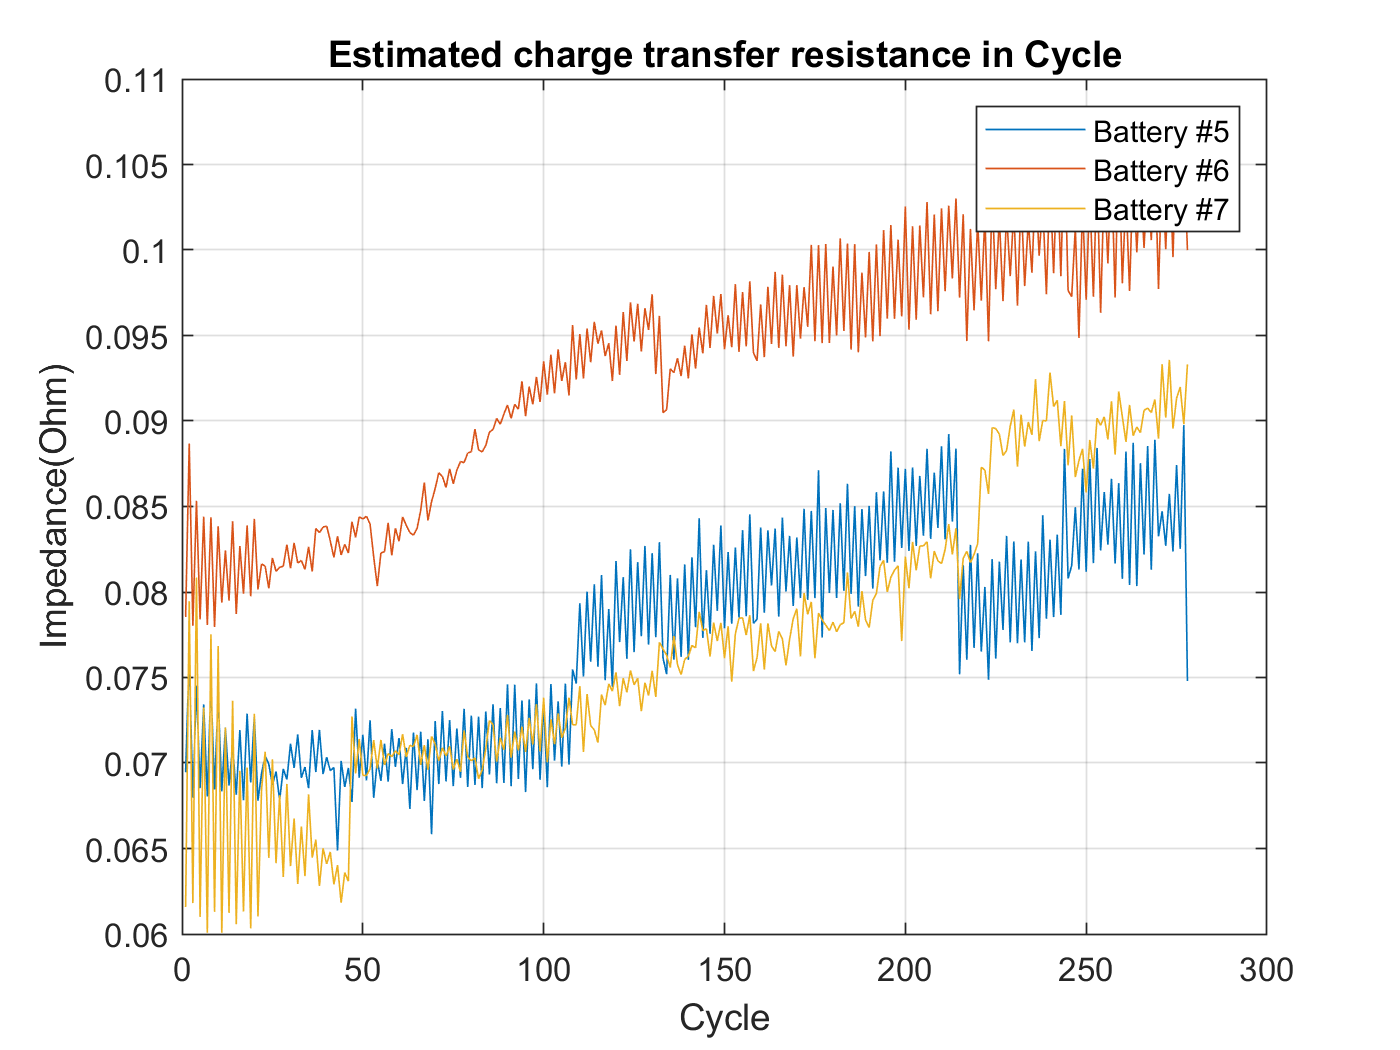

%%%%%%% Rct 

rct5 = extract_impedance_rct(B0005);
rct6 = extract_impedance_rct(B0006);
rct7 = extract_impedance_rct(B0007);
figure
plot(rct5), hold on, plot(rct6), plot(rct7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated charge transfer resistance in Cycle')

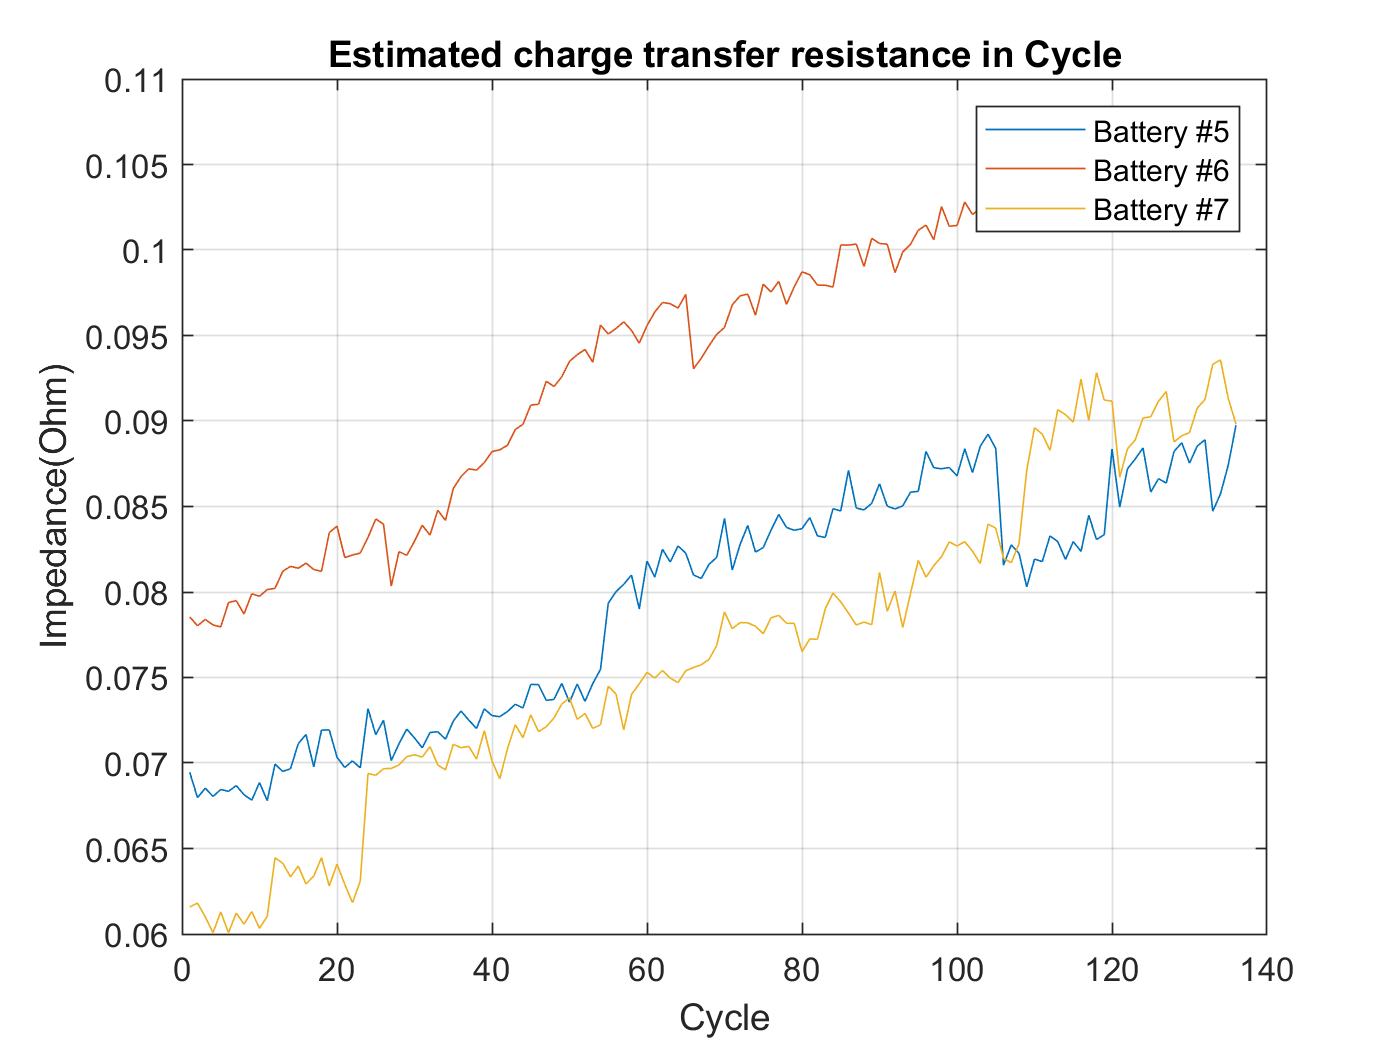


%%%%%%% Rct _charge

rct5 = extract_impedance_rct_charge(B0005);
rct6 = extract_impedance_rct_charge(B0006);
rct7 = extract_impedance_rct_charge(B0007);
figure
plot(rct5), hold on, plot(rct6), plot(rct7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated charge transfer resistance in Cycle')

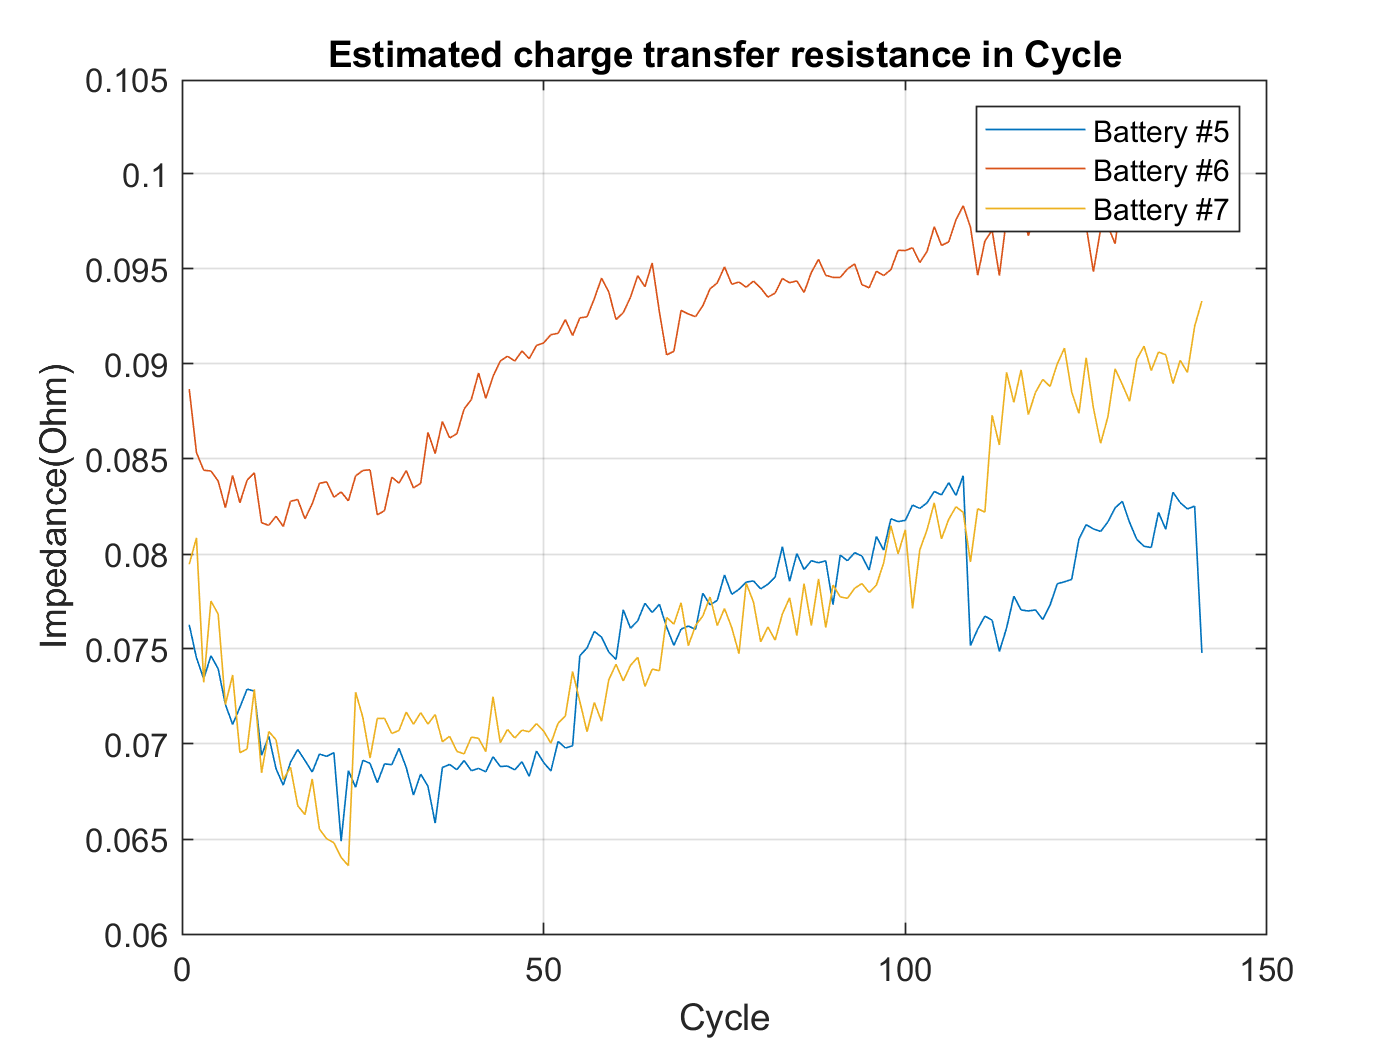


%%%%%%% Rct _discharge

rct5 = extract_impedance_rct_discharge(B0005);
rct6 = extract_impedance_rct_discharge(B0006);
rct7 = extract_impedance_rct_discharge(B0007);
figure
plot(rct5), hold on, plot(rct6), plot(rct7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated charge transfer resistance in Cycle')